

% 2019/3/25
% show deltaTp for sigmoid now between two priors
% change marker for animals: triangle

% 2019/2/18: 
% model-based comparison b/t linear & BLS
% check var(tp|extreme ts)< E(var(tp|priorMean))
% full probabilistic linear model fit:idFitLlinear, estLinear.m

% 2019/1/10: model-free test of sigmodial

% 9/16/2018
% sFig1: distribution of weights
% sFig3: bias-variance (BLS-data)

% 8/31/2018
% rank sum test for overalp: ignoring EH/RL
% supplementary figure 1: copy of figure1 for each condition (ER,EL,HR,HL)
% supplementary figure 2: bias-var (BLS), data vs model

% 8/18/2018
% everythign condition-speciifc (animal, priorX, effector, direction)
% condition-specific BLS fitting

% 8/17/2018
% slope with weighted regression

% 8/3/2018
% stat for # trial/block
% plot tp histogram right after switch @ overlap ts
% plot wm,wp,offset

% 5/10/2018
% plot tp-ts, modified DnPlotResponses2P with PlotDiff

% 4/23/2018
% do stat on linear regression slope for tp-ts

% 3/5/2018
% switching across blocks (bias=f(trials after switch), only overlap?
%   clean up the code using initRSG2prior

% 2/8/2018
% compare bias b/t longest vs shortest ts for each prior

% save NEV, NS3

% note
% save data from around 800 trials in 12/7
% data transfer speed warning issue in 12/13? two cells in NS3 data

% after sumHbehRecord

% ref: analHandEye2PriorRSG.m (daily behavioral check)

## init

initRSG2prior;

iAnimal=1;
fname=fn{iAnimal};
Tmat=T;

idExpFig=0;

idFitBLS=0; % 1; % 0;

idFitLlinear=0; % 1;

## check across-session variability of wm,wp,offset (wFit w/o outlier removal?)

figure; nMeas=4; for iS=1:length(fname) load([behDir 'H_' fname{iS}(end-7:end) '.mat']); % T t idShortTrial idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12) subplot(nMeas,1,1);plot(iS,wFit.w_m,'o'); ylabel('w_m');hold all; subplot(nMeas,1,2);plot(iS,wFit.w_p,'o'); ylabel('w_p');hold all; subplot(nMeas,1,3);plot(iS,wFit.offset1,'o'); ylabel('offset1');hold all; subplot(nMeas,1,4);plot(iS,wFit.offset2,'o'); ylabel('offset2');hold all; end

## outlier removal for each session

also prior-, modality-, direction-, ts-specific

% idOut=[]; rangeOut=[0 3]; pOut=[];
% idPlot=0; % 1;
% for iS=1:nS
%     fid=fname{iS}(end-5:end);
%     if iS==1, fnmTmp=[behDir 'H_20' fid '_3.mat']; else  fnmTmp=[behDir 'H_20' fid '.mat']; end;
%     load(fnmTmp);% T t idShortTrial idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)
%     idOutS=true(size(T)); % assumig all outliers (inc. t<0)
%     for i=1:nPr
%         for j=1:nEH
%             for k=1:nTarg
%                 for m=1:length(Tmat{i})                
%                     id=idShortTrial==(2-i) &... % idShortTrial
%                         idHandEye==(2-j) &...  % idHandEye
%                         theta==(k-1)*180 &... % target location
%                         T==Tmat{i}(m) &...
%                         t>0 & t<3*Tmat{i}(m); % only valid trials for now
%                     u0=rangeOut*Tmat{i}(m); %[0.1 1.9]*overlapT; % [0.5 1.5]*overlapT; %[0 2]*overlapT; % with least outlier removal; or max(t)
%                     [tClean,idClean,pOutTmp,tOut]=removeOutlier(t(id),0,u0); %nSDremoveOutlier);
%                     idOutS(id)=~idClean;
%                     pOut=[pOut;mean(~idClean)];
%                     if idPlot
%                         figure; set(gcf,'position',pplot.(['rect' num2str(k) '_' num2str(m)]));hold all;
%                         histfit(tClean,35); if ~isempty(tOut), plot(tOut,0,'rx'); end; axis tight;
%                         title([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', ts' num2str(Tmat{i}(m)) ', p(outlier): ' num2str(mean(~idClean)*100) '%']);
%                         disp([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', ts' num2str(Tmat{i}(m)) ', p(outlier): ' num2str(mean(~idClean)*100) '%']);
%                         if mean(~idClean)>10
%                             disp('');
%                         end
%                     end                                        
%                 end % m ts
%             end % k targert
%             if idPlot, waitforbuttonpress; close all; end;
%         end % j EH
%     end % prior
%     idOut=[idOut; idOutS];
% end % for iS=1:nS
% save([behDir 'H_RSGprior_DMFC.mat'],'idOut','rangeOut','pOut','-append');
% load([behDir 'H_RSGprior_DMFC.mat'],'T','t','idShortTrial','idHandEye','theta');

load([behDir 'H_RSGprior_DMFC.mat']); % T t idShortTrial idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)

## 2019/3/25

show deltaTp for sigmoid now between two priors 2019/1/10: show behavior is sigmoidal by mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2) 2019/1/10: model comparison with linear model fit getting BIC LogPtp_Meas

% 2019/2/18: 
% model-based comparison b/t linear & BLS
% check var(tp|extreme ts)< E(var(tp|priorMean))
% opacity~# trials for model-free (idUseOp)
% condition-specific marker; red for short, blue for long

idChk=0; % 1;
idChkModel= 0; % 1;
idSep=0; % 1; % separately for shorter and longer ts
idUseOp=1;
sidUni=unique(sessId); % 170823
nSess=length(sidUni);

tmpMarker={'^';'^'}; % {'o';'o'}; % fliplr({'^','o','d','s'}); % {'^','o','d','s'}; % ER>EL>HR>HL
cmapTmp=[1 0 0;0 0 1]; % [0 .6 0;1 .5 0;0 0 1;1 0 0];
markersize=2; % 4;
% optsExpFig.Width=3; % 10/2.54;
% optsExpFig.Height=3; % 7.3/2.54;

if idSep
%     dTp=nan(nSess,nPr,nEH,nTarg,2,2); % last for middle vs extreme
%     nTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
else
    dTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    nTp=nan(nSess,nPr,nEH,nTarg); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    cid=nan(nSess,nPr,nEH,nTarg); % 12345678 pr>EH>RL
end

RMSE=nan(nSess,nPr,nEH,nTarg,2); % BLS linear
vTp=nan(nSess,nPr,nEH,nTarg,nTspp);
mTp=nan(nSess,nPr,nEH,nTarg,nTspp);
resLM=nan(nSess,nPr,nEH,nTarg,nTspp);

if idUseOp
    minOp=0; % 0.8; % 9; % linearly scaled by white and original color (max#trials>original; min#trial>c+(1-c)*0.9
else
    minMS=1; % min marker size
    maxMS=10; % max marker size
end

for iS=length(sidUni):(-1):1 % 1:length(sidUni)
    disp(['===== ' num2str(sidUni(iS)) ' =====']);
    idS=sessId==sidUni(iS);
    
    for i=1:nPr % 1 short 2 long
        for j=1:nEH 
            for l=1:nTarg
                
                id=idShortTrial==(2-i) &... % idShortTrial
                    idHandEye==(2-j) &...            % eye hand
                    theta==180*(l-1) &... % right left
                    idS &... % session
                    ~idOut; % outlier
                
                if idChk
                    idPlot=1; plotTpTs(T(id),t(id),idPlot); setFigPos(1,1);
                    %                     waitforbuttonpress; close;
                end
                
                % get mean tp for each ts
                muTp=nan(length(Tmat{i}),1);
                varTp=nan(length(Tmat{i}),1);
                for k=1:length(Tmat{i})
                    tmpId=id & T==Tmat{i}(k);
                    muTp(k)=mean(t(tmpId));
                    varTp(k)=std(t(tmpId));
%                     disp(nnz(tmpId)); % # data points
                end
                
                % model-based comparison b/t linear & BLS
                wFitTmp=wFitSessCond(iS,j,l);
                nParam=0; % 2;
                % no fitting
                sqErr=@(p,q) sum((muTp(:)-(BLS(q,p(1),[min(q) max(q)],'uniform')+p(2))).^2); % p: wm, offset, ts
                SE0=sqErr([wFitTmp.w_m,wFitTmp.(['offset' num2str(3-i)])],Tmat{i}(:));

                RMSE(iS,i,j,l,1)=sqrt(SE0/(length(Tmat{i})-nParam)); % SE>RMSE (N.B. now taking into account degree of freedom)
                LM=fitlm(Tmat{i},muTp,'linear');
                resLM(iS,i,j,l,:)=table2array(LM.Residuals(:,1));
                RMSE(iS,i,j,l,2)=sqrt(mean((muTp-LM.predict).^2)); % LM.RMSE; N.B. LinearModel's RMSE taking into account degree of freedom
%                 disp(['RMSE(BLS vs linear): ' num2str(RMSE(iS,i,j,l,:))]);
                
                % check var(tp|extreme ts)< E(var(tp|priorMean))
                mTp(iS,i,j,l,:)=muTp;
                vTp(iS,i,j,l,:)=varTp;
                
                if idSep
%                     dTp(iS,i,j,l,1,1)=diff(muTp(2:3));
%                     dTp(iS,i,j,l,2,1)=diff(muTp(3:4));
%                     dTp(iS,i,j,l,1,2)=diff(muTp(1:2));
%                     dTp(iS,i,j,l,2,2)=diff(muTp(4:5));
%                     nTp(iS,i,j,l,1)=nnz(id & T<=median(Tmat{i}));
%                     nTp(iS,i,j,l,2)=nnz(id & T>=median(Tmat{i}));
                else
                    dTp(iS,i,j,l,1)=mean(diff(muTp(2:4)));
                    dTp(iS,i,j,l,2)=mean([diff(muTp(1:2)) diff(muTp(4:5))]);
                    nTp(iS,i,j,l)=nnz(id);
                    cid(iS,i,j,l)=l+(j-1)*nTarg+(i-1)*nEH*nTarg;
                end
                
                if idChk
                    figure; setFigPos(2,1); ha;
                    plot(diff(muTp(3:4)),diff(muTp(4:5)),'o'); 
                    plot(diff(muTp(2:3)),diff(muTp(1:2)),'o'); 
%                     axis tight; 
                    plotIdentity(gca);
                    waitforbuttonpress; close all;
                end
                
            end % l targ
        end % j EH
    end % i pr
end % sess

===== 161223 =====
===== 161222 =====
===== 161221 =====
===== 161220 =====
===== 161219 =====
===== 161218 =====
===== 161215 =====
===== 161214 =====
===== 161212 =====
===== 161211 =====
===== 161210 =====
===== 161208 =====
===== 161207 =====
===== 161206 =====
===== 161205 =====
===== 161204 =====
===== 161203 =====



nTp0=nTp; nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
cid=cid(:);
disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);

# trials: 309, 85


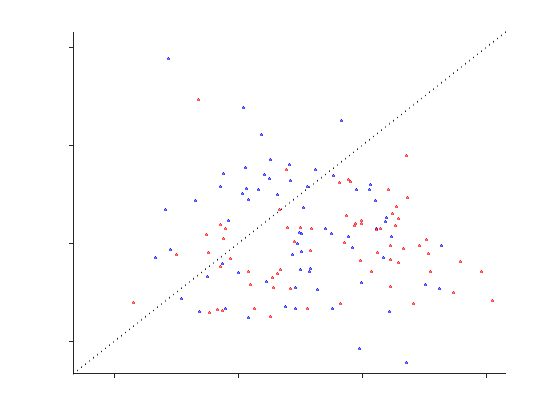


figure; ha; setFigPos(1,2); % scatter plot for model free
if idSep
%     tmpX=dTp(:,:,:,:,:,1); tmpY=dTp(:,:,:,:,:,2);
%     tmpX=tmpX(:);tmpY=tmpY(:);
%     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
else
    tmpX=dTp(:,:,:,:,1); tmpX=tmpX(:);
    tmpY=dTp(:,:,:,:,2); tmpY=tmpY(:);
%     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
%     cid=cid(:);
end
% disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);
for i=1:length(nTp)
    if idUseOp
        % condition<prior-specific marker; red for short, blue for long
        idShortTmp=cid(i)<=(nEH*nTarg); % 1 for short, 0 for long
        cidTmp=cid(i)-(1-idShortTmp)*nEH*nTarg; % 1234 for ER EL HR HL
        tmpC=cmapTmp(2-idShortTmp,:);
%         tmpC=pplot.cmap{3-2*idShortTmp}; % red for short, blue for long
        tmpC=tmpC+(1-tmpC)*minOp*(1-tmpMS(i));
        plot(tmpX(i),tmpY(i),tmpMarker{2-idShortTmp},... % fliplr({'^','o','d','s'});
            'color',tmpC,'markersize',markersize,'linewidth',0.5); 
    else % idUseOp
        plot(tmpX(i),tmpY(i),'ko','markersize',tmpMS(i)*(maxMS-minMS)+minMS);
    end
end
axis tight; 
xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out'); 
plotIdentity(gca);
ylabel('difference in mean t_p for boundary t_s');
xlabel('difference in mean t_p for middle t_s');
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);


% stat separately for short/long
idShortTmp=cid<=(nEH*nTarg);
[p,h]=signrank(tmpX(idShortTmp),tmpY(idShortTmp)); disp(['short: ' num2str(p,3)]);

short: 3.77e-10


[p,h]=signrank(tmpX(~idShortTmp),tmpY(~idShortTmp)); disp(['long: ' num2str(p,3)]);

long: 0.00137


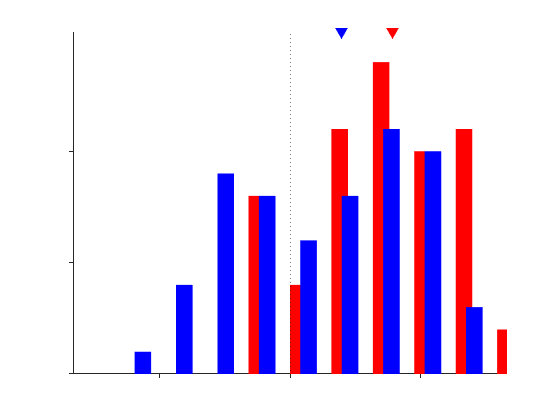


% save('deltaTp_H.mat','tmpY','tmpX','cid');

% histogram: now condition-specific<prior-specific
figure; ha; setFigPos(1,3);
% hHist=histogram(tmpY-tmpX,25);
% set(hHist,'Facecolor','w');
% plotVertical(gca,0,[]);
% ylabel('# data sets');
% xlabel('degree of being sigmoidal');
nBin=20;barWidth=0.4;markersize=10;
xHist=linspace(min(tmpY-tmpX),max(tmpY-tmpX),nBin); % getting bin locations
idShortTmp=cid<=(nEH*nTarg); % 1 for short, 0 for long
% plot
diffYX=cell(nPr,1);
for i=1:nPr   
%      idCondTmp=i==(mod(cid-1,4)+1); % 12341234
%     diffXY{i}=-(tmpY(idCondTmp)-tmpX(idCondTmp));
    diffYX{i}=tmpY(i==(2-idShortTmp))-tmpX(i==(2-idShortTmp)); % 2-idShortTmp: 1 for short, 2 for long
    hHist=histogram(-diffYX{i},xHist);
     Xval    = hHist.BinEdges + hHist.BinWidth*0.5 +hHist.BinWidth*(i-1)/(nEH*nTarg)+1/(nEH*nTarg*2); % (i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
     Xval    = Xval(1:end-1);
     Yval    = hHist.Values;
     delete(hHist);

        tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
     hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',tmpC,'EdgeColor','none'); %  pplot.cmap{2*i-1}
end
axis tight; 
maxYlim=max(ylim);
% plot mean
for i=1:nPr
         tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    plot(mean(-diffYX{i}),1.1*maxYlim,'color',tmpC,'markerfacecolor',tmpC,'marker','v','markersize',markersize); %  pplot.cmap{2*i-1}
end % for i=1:nPr
ylabel('# data sets');
xlabel('degree of being sigmoidal');
plotVertical(gca,0,[]);
set(gca,'tickdir','out','xtick',-60:30:60,'ytick',0:5:10); xlim([-50 50]);
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);


% return;

## full probabilistic linear model fit: idFitLlinear, estLinear.m: everythign condition-speciifc (animal, priorX, effector, direction)

redo for 161206 161207 161210 161221 change estWmWpOld: nInitW: 6>15, nInit5>10, also increase offset10, offset20 (1.5>3, 0.5>1.5)

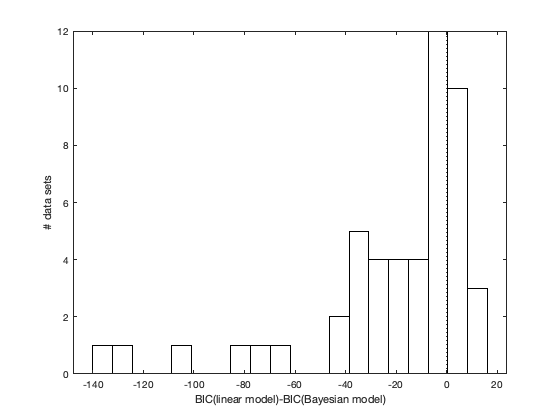

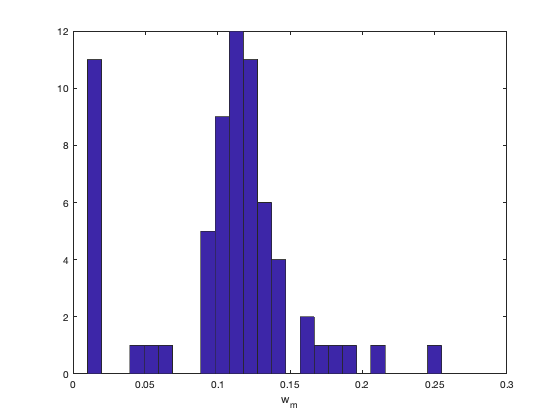

% check result
figure; setFigPos(1,1); h=histogram(bicLinearSessCond(:)-bicSessCond(:),20); set(h,'facecolor','w');
xlabel('BIC(linear model)-BIC(Bayesian model)'); ylabel('# data sets'); plotVertical(gca,0,[]);
figure; setFigPos(2,1); hist([wFitLinearSessCond.w_m],25); xlabel('w_m');
figure; setFigPos(2,2); hist([wFitLinearSessCond.w_p],25); xlabel('w_p');
figure; setFigPos(2,3); hist([wFitLinearSessCond.sS],25); xlabel('slope(short)');
figure; setFigPos(2,4); hist([wFitLinearSessCond.sL],25); xlabel('slope(long)');

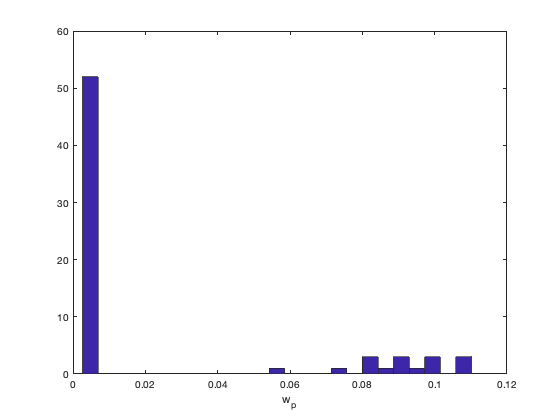

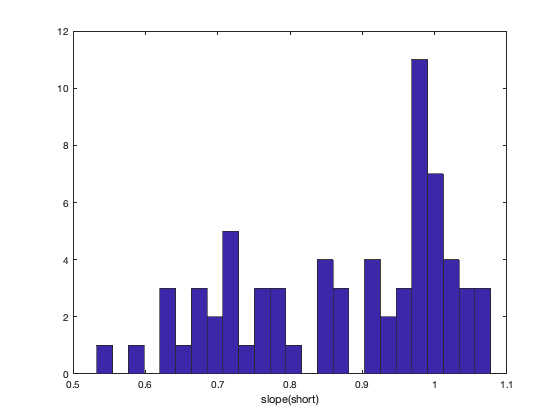

figure; setFigPos(2,5); hist([wFitLinearSessCond.b0S],25); xlabel('intercept(short)');

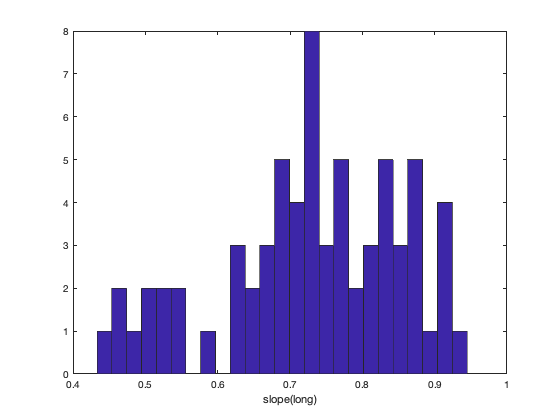

figure; setFigPos(2,6); hist([wFitLinearSessCond.b0L],25); xlabel('intercept(long)');


if idFitLlinear
    
    sidUni=unique(sessId);
    bicLinearSessCond=nan(length(sidUni),nEH,nTarg); % ,nPr
    if exist('wFitSessCond') % redo
        wFitSessCond0=wFitSessCond;
    end
    wFitLinearSessCond=[];
    for iS=length(sidUni):(-1):1 % 1:length(sidUni)
        disp(['===== ' num2str(sidUni(iS)) ' =====']);
        idS=sessId==sidUni(iS);
        
        % redo
%         if sidUni(iS)==161206 | sidUni(iS)==161207 | sidUni(iS)==161210 | sidUni(iS)==161221 % redo for 161206 161207 161210 161221
            
            %     for i=1:nPr
            for j=1:nEH
                for l=1:nTarg
                    
                    % redo
                    disp([wFitSessCond0(iS,j,l).w_m(:) wFitSessCond0(iS,j,l).w_p(:) wFitSessCond0(iS,j,l).offset1(:) wFitSessCond0(iS,j,l).offset2(:)]);
                    
                    id=... % idShortTrial==(2-i) &... % idShortTrial
                        idHandEye==(2-j) &...            % eye hand
                        theta==180*(l-1) &... % right left
                        idS &... % session
                        ~idOut; % outlier
                    
                    try
                        %                     [wFitTmp,bicTmp]=estWmWpOld(t(id),T(id),true(nnz(id),1),'mmse1Wm',[],-1,true); % display: off
                        [wFitTmp,bicTmp]=estLinear(t(id),T(id),idShortTrial(id),'mmse2offset',[],-1,true); % display: off
                    catch
                        disp('');
                    end
                    fieldnm=fieldnames(wFitTmp);
                    for iField=1:length(fieldnm)
                        wFitLinearSessCond(iS,j,l).(fieldnm{iField})=wFitTmp.(fieldnm{iField}); % mmse2offset: w_m w_p offset1 offset2 ,i
                    end
                    try
                        bicLinearSessCond(iS,j,l)=bicTmp;
                    catch
                        disp(bicTmp);
                    end
                    disp([wFitTmp.w_m(:) wFitTmp.w_p(:) wFitTmp.sS(:) wFitTmp.sL(:) wFitTmp.b0S(:) wFitTmp.b0L(:)]);
                end % l targ
            end % j EH
            %     end % i pr
            
            % redo
%         end % if sidUni(iS)==161206 | sidUni(iS)==161207 | sidUni(iS)==161210 | sidUni(iS)==161221
        
    end % serss
    save([behDir 'H_RSGprior_DMFC.mat'],'wFitLinearSessCond','bicLinearSessCond','-append');

return;


end % if idFitLlinear

## checking condition-speciifc BLS fit: mean +- SD across sessions

wFitSessCond [17 x 2EH x 2RL]. w_m w_p offset1 offset2

for iEH=1:nEH
    for iRL=1:nTarg
        [m,s]=meanSD([wFitSessCond(:,iEH,iRL).w_m]); % wm
        disp([num2str(m,3) '  ' num2str(s,3)]);
        [m,s]=meanSD([wFitSessCond(:,iEH,iRL).w_p]); % wp
        disp([num2str(m,3) '  ' num2str(s,3)]);
        [m,s]=meanSD([wFitSessCond(:,iEH,iRL).offset2]); % offset2
        disp([num2str(m,3) '  ' num2str(s,3)]);
        [m,s]=meanSD([wFitSessCond(:,iEH,iRL).offset1]); % offset1 for long
        disp([num2str(m,3) '  ' num2str(s,3)]);
        disp('-----');
    end
end

0.0266  0.00904


0.0772  0.0325


0.847  18.4


-10.8  23.1


-----


0.0425  0.0159


0.0861  0.0219


23.4  23.7


-4.16  20.5


-----


0.062  0.0259


0.0841  0.0208


9.25  31.8


5.77  26.6


-----


0.0853  0.0249


0.0855  0.0203


0.394  29.1


-42  34.7


-----


## rank sum test for overalp: ignoring EH/RL

idS=T==800 & idShortTrial==1 & t>0 & t<3*T & ~idOut;
idL=T==800 & idShortTrial==0 & t>0 & t<3*T & ~idOut;
[p,h,stat]=ranksum(t(idS),t(idL),'tail','left')

p = 5.4452e-45

h = logical
   1


stat = struct with fields:
       zval: -14.0255
    ranksum: 5.3412e+06



% p =
% 
%    1.1606e-44
% 
% 
% h =
% 
%   logical
% 
%    1
% 
% 
% stat = 
% 
%   struct with fields:
% 
%        zval: -13.9717
%     ranksum: 5.3906e+06

% mean(t(idS))
% 
% ans =
% 
%   794.0296
% 
% mean(t(idL))
% 
% ans =
% 
%   830.4956

## 2019/1/10: show behavior is sigmoidal by mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)

2019/1/10: model comparison with linear model fit getting BIC LogPtp_Meas

% 2019/2/18: 
% model-based comparison b/t linear & BLS
% check var(tp|extreme ts)< E(var(tp|priorMean))
% opacity~# trials for model-free (idUseOp)
% condition-specific marker; red for short, blue for long

idChk=0; % 1;
idChkModel= 0; % 1;
idSep=0; % 1; % separately for shorter and longer ts
idUseOp=1;
sidUni=unique(sessId); % 170823
nSess=length(sidUni);

tmpMarker=fliplr({'^','o','d','s'}); % {'^','o','d','s'}; % ER>EL>HR>HL
cmapTmp=[0 .6 0;1 .5 0;0 0 1;1 0 0];
markersize=2; % 4;
% optsExpFig.Width=3; % 10/2.54;
% optsExpFig.Height=3; % 7.3/2.54;

if idSep
%     dTp=nan(nSess,nPr,nEH,nTarg,2,2); % last for middle vs extreme
%     nTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
else
    dTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    nTp=nan(nSess,nPr,nEH,nTarg); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    cid=nan(nSess,nPr,nEH,nTarg); % 12345678 pr>EH>RL
end

RMSE=nan(nSess,nPr,nEH,nTarg,2); % BLS linear
vTp=nan(nSess,nPr,nEH,nTarg,nTspp);
mTp=nan(nSess,nPr,nEH,nTarg,nTspp);
resLM=nan(nSess,nPr,nEH,nTarg,nTspp);

if idUseOp
    minOp=0; % 0.8; % 9; % linearly scaled by white and original color (max#trials>original; min#trial>c+(1-c)*0.9
else
    minMS=1; % min marker size
    maxMS=10; % max marker size
end

for iS=length(sidUni):(-1):1 % 1:length(sidUni)
    disp(['===== ' num2str(sidUni(iS)) ' =====']);
    idS=sessId==sidUni(iS);
    
    for i=1:nPr % 1 short 2 long
        for j=1:nEH 
            for l=1:nTarg
                
                id=idShortTrial==(2-i) &... % idShortTrial
                    idHandEye==(2-j) &...            % eye hand
                    theta==180*(l-1) &... % right left
                    idS &... % session
                    ~idOut; % outlier
                
                if idChk
                    idPlot=1; plotTpTs(T(id),t(id),idPlot); setFigPos(1,1);
                    %                     waitforbuttonpress; close;
                end
                
                % get mean tp for each ts
                muTp=nan(length(Tmat{i}),1);
                varTp=nan(length(Tmat{i}),1);
                for k=1:length(Tmat{i})
                    tmpId=id & T==Tmat{i}(k);
                    muTp(k)=mean(t(tmpId));
                    varTp(k)=std(t(tmpId));
%                     disp(nnz(tmpId)); % # data points
                end
                
                % model-based comparison b/t linear & BLS
                wFitTmp=wFitSessCond(iS,j,l);
                nParam=0; % 2;
                % no fitting
                sqErr=@(p,q) sum((muTp(:)-(BLS(q,p(1),[min(q) max(q)],'uniform')+p(2))).^2); % p: wm, offset, ts
                SE0=sqErr([wFitTmp.w_m,wFitTmp.(['offset' num2str(3-i)])],Tmat{i}(:));
%                 [wm,offset,SE]=LSEfitBLS(muTp,Tmat{i},wFitTmp.w_m,wFitTmp.(['offset' num2str(3-i)])); % offset1 for long
%                 disp(['wm: ' num2str(wFitTmp.w_m) ' vs ' num2str(wm)]);
%                 disp(['offset: ' num2str(wFitTmp.(['offset' num2str(3-i)])) ' vs ' num2str(offset)]);
%                 if idChkModel
%                     figure; setFigPos(2,3); ha;  plot(Tmat{i},BLS(Tmat{i},wFitTmp.w_m,[min(Tmat{i}) max(Tmat{i})],'uniform')+wFitTmp.(['offset' num2str(3-i)]),'bo-'); plot(Tmat{i},muTp,'ro-'); 
%                     plot(Tmat{i},BLS(Tmat{i},wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset,'go-'); legend('old BLS','raw data','new LSE BLS fit','location','northwest'); plotIdentity(gca);
%                     applytofig4keynote;
%                     waitforbuttonpress; close;
%                 end
                RMSE(iS,i,j,l,1)=sqrt(SE0/(length(Tmat{i})-nParam)); % SE>RMSE (N.B. now taking into account degree of freedom)
                LM=fitlm(Tmat{i},muTp,'linear');
                resLM(iS,i,j,l,:)=table2array(LM.Residuals(:,1));
                RMSE(iS,i,j,l,2)=sqrt(mean((muTp-LM.predict).^2)); % LM.RMSE; N.B. LinearModel's RMSE taking into account degree of freedom
%                 disp(['RMSE(BLS vs linear): ' num2str(RMSE(iS,i,j,l,:))]);
                
                % check var(tp|extreme ts)< E(var(tp|priorMean))
                mTp(iS,i,j,l,:)=muTp;
                vTp(iS,i,j,l,:)=varTp;
                
                if idSep
%                     dTp(iS,i,j,l,1,1)=diff(muTp(2:3));
%                     dTp(iS,i,j,l,2,1)=diff(muTp(3:4));
%                     dTp(iS,i,j,l,1,2)=diff(muTp(1:2));
%                     dTp(iS,i,j,l,2,2)=diff(muTp(4:5));
%                     nTp(iS,i,j,l,1)=nnz(id & T<=median(Tmat{i}));
%                     nTp(iS,i,j,l,2)=nnz(id & T>=median(Tmat{i}));
                else
                    dTp(iS,i,j,l,1)=mean(diff(muTp(2:4)));
                    dTp(iS,i,j,l,2)=mean([diff(muTp(1:2)) diff(muTp(4:5))]);
                    nTp(iS,i,j,l)=nnz(id);
                    cid(iS,i,j,l)=l+(j-1)*nTarg+(i-1)*nEH*nTarg;
                end
                
                if idChk
                    figure; setFigPos(2,1); ha;
                    plot(diff(muTp(3:4)),diff(muTp(4:5)),'o'); 
                    plot(diff(muTp(2:3)),diff(muTp(1:2)),'o'); 
%                     axis tight; 
                    plotIdentity(gca);
                    waitforbuttonpress; close all;
                end
                
            end % l targ
        end % j EH
    end % i pr
end % sess

===== 161223 =====
===== 161222 =====
===== 161221 =====
===== 161220 =====
===== 161219 =====
===== 161218 =====
===== 161215 =====
===== 161214 =====
===== 161212 =====
===== 161211 =====
===== 161210 =====
===== 161208 =====
===== 161207 =====
===== 161206 =====
===== 161205 =====
===== 161204 =====
===== 161203 =====



nTp0=nTp; nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
cid=cid(:);
disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);

# trials: 309, 85


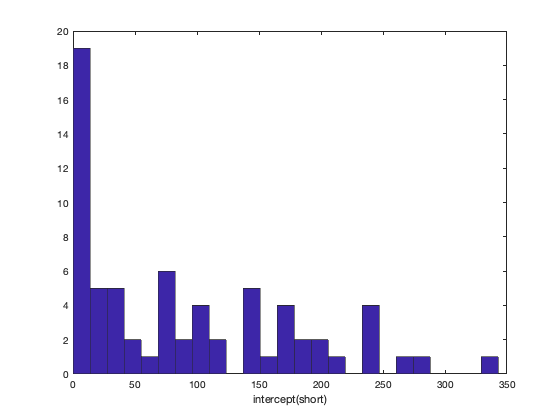

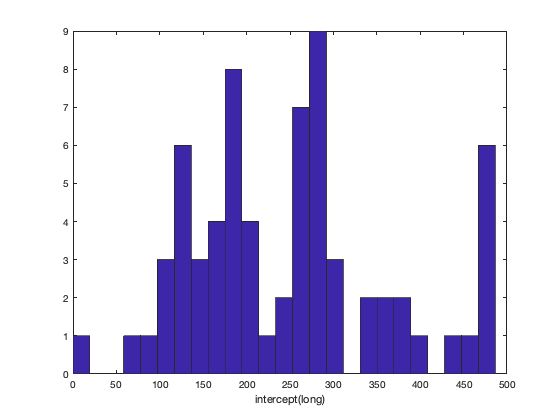


% % model-based comparison b/t linear & BLS
% figure; ha; setFigPos(2,1); % scatter plot for model free
% tmpX=RMSE(:,:,:,:,1); tmpX=tmpX(:);
% tmpY=RMSE(:,:,:,:,2); tmpY=tmpY(:);
% for i=1:length(nTp)
%     if idUseOp
%         % condition-specific marker; red for short, blue for long
%         idShortTmp=cid(i)<=(nEH*nTarg); % 1 for short, 0 for long
%         tmpC=pplot.cmap{3-2*idShortTmp}; % red for short, blue for long
%         tmpC=tmpC+(1-tmpC)*minOp*(1-tmpMS(i));
%         plot(tmpX(i),tmpY(i),tmpMarker{cid(i)-(1-idShortTmp)*nEH*nTarg},...
%             'color',tmpC,'markersize',markersize,'linewidth',0.5);
%     else % idUseOp
%         plot(tmpX(i),tmpY(i),'ko','markersize',tmpMS(i)*(maxMS-minMS)+minMS);
%     end
% end
% axisEqual; % axis tight; 
% % xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out'); 
% plotIdentity(gca);
% ylabel('RMSE(linear model)');
% xlabel('RMSE(Bayesian model)');
% remTickLabel;remLabel;
% applytofig(gcf,optsExpFig);
% % figure; h=histogram(tmpX-tmpY,25); set(h,'facecolor','w'); applytofig4keynote

% % check linear model's residual
% figure; ha; setFigPos(2,1); % scatter plot for model free
% for i=1:size(resLM,1)
%     for j=1:size(resLM,3) % EH
%         for k=1:size(resLM,4) % targ
%             for iPr=1:size(resLM,2)
%             plot(Tmat{iPr}(:),squeeze(resLM(i,iPr,j,k,:)),'-','color',pplot.cmap{2*(iPr-1)+1});
%             end
%         end
%     end
% end
% for iPr=1:size(resLM,2) % plot mean
%     tmpY=squeeze(resLM(:,iPr,:,:,:));
%     tmpY=reshape(tmpY,size(resLM,1)*size(resLM,3)*size(resLM,4),size(resLM,5));
%     shadedErrorBar(Tmat{iPr}(:),mean(tmpY,1),sem(tmpY,1),{'-','color',pplot.cmap{2*(iPr-1)+1},'linewidth',2});
% %     plot(Tmat{iPr}(:),squeeze(mean(mean(mean(tmpY,1),3),4)),'-','color',pplot.cmap{2*(iPr-1)+1},'linewidth',2);
% end
% axis tight; 
% plotHorizon(gca,0,[]);
% xlabel('t_s (ms)');
% ylabel('Residual of linear model');
% % figure; histogram(tmpY(:,1),15);

% % check var(tp|extreme ts)< E(var(tp|priorMean))
% tmpX=mTp(:); tmpY=vTp(:); nTp0=(nTp0-min(nTp))./(max(nTp)-min(nTp));
% % figure 1: sigma vs mu (only extreme ts & prior mean)
% figure; ha; setFigPos(2,2);
% for i=1:nPr
%     for j=1:(nEH*nTarg)
%         iEH=floor((j-1)/nTarg)+1; iTarg=mod(j-1,nTarg)+1;
%         for k=1:2:5 % ts
%             for iS=1:size(mTp,1)
%                 if idUseOp
%                     tmpC=tmpCmap{i,1}(k,:); %
%                     tmpC=tmpC+(1-tmpC)*minOp*(1-nTp0(iS,i,iEH,iTarg));
%                     plot(mTp(:,i,iEH,iTarg,k),vTp(:,i,iEH,iTarg,k),tmpMarker{j},'color',tmpC,'markersize',markersize,'linewidth',0.5);
%                 else
%                     plot(mTp(:,i,iEH,iTarg,k),vTp(:,i,iEH,iTarg,k),tmpMarker{j},'color',tmpCmap{i,1}(k,:),'markersize',markersize,'linewidth',0.5);
%                 end
%             end % iS
%         end % k
%     end % j
% end % i
% for i=1:nPr % plot mean
%     for k=5:(-2):1 % 1:2:5 % ts
%             tmpX=squeeze(mTp(:,i,:,:,k)); tmpX=tmpX(:);
%             tmpY=squeeze(vTp(:,i,:,:,k)); tmpY=tmpY(:);
%             if k==3 % plot line for reference in prior mean
%                 plot(Tmat{i},Tmat{i}*mean(tmpY)/mean(tmpX),':','color',pplot.cmap{2*(i-1)+1});
%             end
%             plotErrorbar(mean(tmpX),std(tmpX),mean(tmpY),std(tmpY),tmpCmap{i,1}(k,:),2); % last for linewdith
%             plot(mean(tmpX),mean(tmpY),'o','markersize',12,'linewidth',2,'color',tmpCmap{i,1}(k,:),'markerfacecolor','w');
%     end
% end
% % axisEqual; % axis tight; 
% % xlim([20 125]);ylim([20 125]); 
% set(gca,'xtick',unique([Tmat{1}(1:2:end)' Tmat{2}(1:2:5)']),'tickdir','out');  % ,'ytick',30:30:120,'tickdir','out'); 
% xlabel('\mu(t_p|t_s)');
% ylabel('\sigma(t_p|t_s)');
% remTickLabel;remLabel;
% applytofig(gcf,optsExpFig);
% % figure 2: observed sigma vs expected sigma
% figure; ha; setFigPos(2,3);
% tmpV=nan(nPr,nTspp-3,2,size(vTp,1)*size(vTp,3)*size(vTp,4)); % last for obs/exp
% iTmpV=1;
% for iS=1:size(vTp,1)
%     for i=1:size(vTp,2)
%         for j=1:size(vTp,3)
%             for k=1:size(vTp,4)
%                 cv=vTp(iS,i,j,k,3)/Tmat{i}(3); % mTp(iS,i,j,k,3); % based on ts, not mu(tp)
%                 tmpY=cv*Tmat{i}(1); tmpX=vTp(iS,i,j,k,1); tmpC=tmpCmap{i,1}(1,:); tmpC=tmpC+(1-tmpC)*minOp*(1-nTp0(iS,i,j,k)); % ts1
%                 tmpV(i,1,:,iTmpV)=[tmpX tmpY];
%                 plot(tmpX,tmpY,tmpMarker{(j-1)*nTarg+k},'color',tmpC,'markersize',markersize,'linewidth',0.5);
%                 tmpY=cv*Tmat{i}(5); tmpX=vTp(iS,i,j,k,5); tmpC=tmpCmap{i,1}(5,:); tmpC=tmpC+(1-tmpC)*minOp*(1-nTp0(iS,i,j,k)); % ts5
%                 tmpV(i,2,:,iTmpV)=[tmpX tmpY];
%                 plot(tmpX,tmpY,tmpMarker{(j-1)*nTarg+k},'color',tmpC,'markersize',markersize,'linewidth',0.5);
%                 iTmpV=iTmpV+1;
%             end
%         end
%     end
% end
% axisEqual; % axis tight; 
% % xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out'); 
% plotIdentity(gca);
% xlabel('observed \sigma(t_p|t_s)');
% ylabel('expected \sigma(t_p|t_s)');
% remTickLabel;remLabel;
% applytofig(gcf,optsExpFig);
% % stat
% [p,h]=signrank(squeeze(tmpV(1,1,1,:)),squeeze(tmpV(1,1,2,:))); disp(p); % 480
% [p,h]=signrank(squeeze(tmpV(1,2,1,:)),squeeze(tmpV(1,2,2,:))); disp(p); % short800
% [p,h]=signrank(squeeze(tmpV(2,1,1,:)),squeeze(tmpV(2,1,2,:))); disp(p);
% [p,h]=signrank(squeeze(tmpV(2,2,1,:)),squeeze(tmpV(2,2,2,:))); disp(p);

figure; ha; setFigPos(1,2); % scatter plot for model free

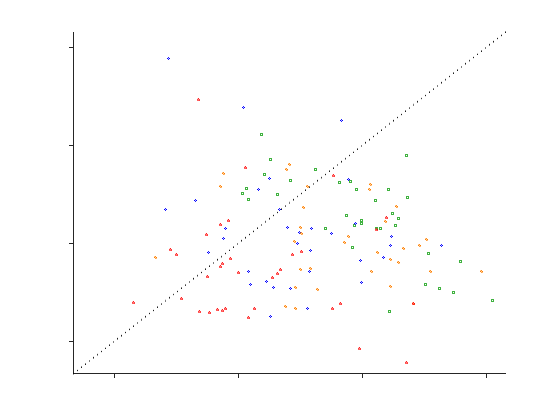

if idSep
%     tmpX=dTp(:,:,:,:,:,1); tmpY=dTp(:,:,:,:,:,2);
%     tmpX=tmpX(:);tmpY=tmpY(:);
%     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
else
    tmpX=dTp(:,:,:,:,1); tmpX=tmpX(:);
    tmpY=dTp(:,:,:,:,2); tmpY=tmpY(:);
%     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
%     cid=cid(:);
end
% disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);
for i=1:length(nTp)
    if idUseOp
        % condition<prior-specific marker; red for short, blue for long
        idShortTmp=cid(i)<=(nEH*nTarg); % 1 for short, 0 for long
        cidTmp=cid(i)-(1-idShortTmp)*nEH*nTarg; % 1234 for ER EL HR HL
        tmpC=cmapTmp(cidTmp,:);
%         tmpC=pplot.cmap{3-2*idShortTmp}; % red for short, blue for long
        tmpC=tmpC+(1-tmpC)*minOp*(1-tmpMS(i));
        plot(tmpX(i),tmpY(i),tmpMarker{cidTmp},... % fliplr({'^','o','d','s'});
            'color',tmpC,'markersize',markersize,'linewidth',0.5); 
    else % idUseOp
        plot(tmpX(i),tmpY(i),'ko','markersize',tmpMS(i)*(maxMS-minMS)+minMS);
    end
end
axis tight; 
xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out'); 
plotIdentity(gca);
ylabel('difference in mean t_p for boundary t_s');
xlabel('difference in mean t_p for middle t_s');
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);


[p,h]=signrank(tmpX,tmpY); disp(['sigmoid: pooled across sessions,prior,effector,direction: ' num2str(p,3)]);

sigmoid: pooled across sessions,prior,effector,direction: 7.56e-12



% stat for each condition; pooled across prior
for i=1:(length(unique(cid))/nPr)
    idCondTmp=i==(mod(cid-1,4)+1); % 12341234
    [p,h]=signrank(tmpX(idCondTmp),tmpY(idCondTmp)); disp(['cond' num2str(i) ': ' num2str(p,3)]);
end

cond1: 0.000175
cond2: 1.46e-05
cond3: 0.0106
cond4: 0.00241


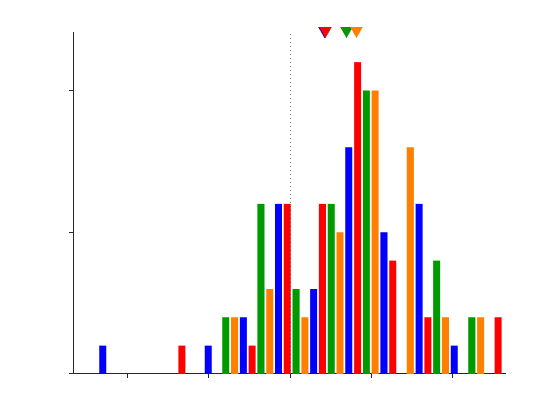

% for i=1:length(unique(cid))
%     idCondTmp=i==cid;
%     [p,h]=signrank(tmpX(idCondTmp),tmpY(idCondTmp)); disp(['cond' num2str(i) ': ' num2str(p,3)]);
% end

% % stat separately for short/long
% idShortTmp=cid<=(nEH*nTarg);
% [p,h]=signrank(tmpX(idShortTmp),tmpY(idShortTmp)); disp(['short: ' num2str(p,3)]);
% [p,h]=signrank(tmpX(~idShortTmp),tmpY(~idShortTmp)); disp(['long: ' num2str(p,3)]);

% histogram: now condition-specific<prior-specific
figure; ha; setFigPos(1,3);
% hHist=histogram(tmpY-tmpX,25);
% set(hHist,'Facecolor','w');
% plotVertical(gca,0,[]);
% ylabel('# data sets');
% xlabel('degree of being sigmoidal');
nBin=15;barWidth=0.2;markersize=10;
xHist=linspace(min(tmpY-tmpX),max(tmpY-tmpX),nBin); % getting bin locations
idShortTmp=cid<=(nEH*nTarg); % 1 for short, 0 for long
% plot
diffXY=cell(nPr,1);
for i=1:(length(unique(cid))/nPr) % nPr   
     idCondTmp=i==(mod(cid-1,4)+1); % 12341234
    diffXY{i}=-(tmpY(idCondTmp)-tmpX(idCondTmp));
%     diffYX{i}=tmpY(i==(2-idShortTmp))-tmpX(i==(2-idShortTmp)); % 2-idShortTmp: 1 for short, 2 for long
    hHist=histogram(diffXY{i},xHist);
     Xval    = hHist.BinEdges + hHist.BinWidth*0.5 +hHist.BinWidth*(i-1)/(nEH*nTarg)+1/(nEH*nTarg*2); % (i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
     Xval    = Xval(1:end-1);
     Yval    = hHist.Values;
     delete(hHist);

        tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
     hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',tmpC,'EdgeColor','none'); %  pplot.cmap{2*i-1}
end
axis tight; 
maxYlim=max(ylim);
% plot mean
for i=1:(length(unique(cid))/nPr) % nPr
         tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    plot(mean(diffXY{i}),1.1*maxYlim,'color',tmpC,'markerfacecolor',tmpC,'marker','v','markersize',markersize); %  pplot.cmap{2*i-1}
end % for i=1:nPr
ylabel('# data sets');
xlabel('degree of being sigmoidal');
plotVertical(gca,0,[]);
set(gca,'tickdir','out','xtick',-60:30:60,'ytick',0:5:10); xlim([-80 80]);
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);


% % check BLS predict higher sigmoid for long prior
% teS=BLS(480:80:800,0.0508,[480 800],'uniform');
% teL=BLS(800:100:1200,0.0508,[800 1200],'uniform');
% x=diff(teS);
% y=diff(teL);
% mean([x(1) x(4)])-mean([x(2) x(3)]) % -23.7240
% mean([y(1) y(4)])-mean([y(2) y(3)]) % -33.1630

% % scatter hist diff
% figure; ha; setFigPos(1,4);
% scatterHistDiff(tmpX,tmpY,[],[],[]);

% return;

## BLS fit for each sessions: everythign condition-speciifc (animal, priorX, effector, direction)

redo for 161206 161207 161210 161221 change estWmWpOld: nInitW: 6>15, nInit5>10, also increase offset10, offset20 (1.5>3, 0.5>1.5)

if idFitBLS
    % conditon, pooled across sessions
    bicCond=nan(nEH,nTarg); % ,nPr
    wFitCond=[];
        
        %     for i=1:nPr
        for j=1:nEH
            for l=1:nTarg
                        disp(['===== ' ehNm{j} targNm{l}  ' =====']);

                id=... % idShortTrial==(2-i) &... % idShortTrial
                    idHandEye==(2-j) &...            % eye hand
                    theta==180*(l-1) &... % right left
                    ~idOut; % outlier % t<0 & t>3*T already removed
                
                try
                    %                     [wFitTmp,bicTmp]=estWmWpOld(t(id),T(id),true(nnz(id),1),'mmse1Wm',[],-1,true); % display: off
                    [wFitTmp,bicTmp]=estWmWpOld(t(id),T(id),idShortTrial(id),'mmse2offset',[],-1,true); % display: off
                catch
                    disp('');
                end
                fieldnm=fieldnames(wFitTmp);
                for iField=1:length(fieldnm)
                    wFitCond(j,l).(fieldnm{iField})=wFitTmp.(fieldnm{iField}); % mmse2offset: w_m w_p offset1 offset2 ,i
                end
                try
                    bicCond(j,l)=bicTmp;
                catch
                    disp(bicTmp);
                end
                disp([wFitTmp.w_m(:) wFitTmp.w_p(:) wFitTmp.offset1(:) wFitTmp.offset2(:)]);
            end % l targ
        end % j EH
        %     end % i pr
    save([behDir 'H_RSGprior_DMFC.mat'],'wFitCond','bicCond','-append');

## session

% ===== 161203 ===== % ===== 161204 ===== % ===== 161205 ===== % ===== 161206 ===== % 0.0346 0.0346 0.1011 0.1011 % % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 74166.355550 seconds. % 0.0346 0.1011 42.6978 34.4947 % % 0.0484 0.1057 -17.9160 26.4338 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 69466.008326 seconds. % 0.0484 0.1057 -17.9159 26.4339 % % 0.0318 0.1123 11.1901 -5.2242 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 76480.161767 seconds. % 1.0e+03 * % % 5.6685 % 5.6685 % % 0.0318 0.0318 0.1123 0.1123 % % 0.0656 0.1127 -32.7728 -14.6426

% ===== 161210 ===== % 0.0174 0.0174 0.1209 0.1209 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 105901.915379 seconds. % 0.0174 0.1209 -27.5291 10.1091 % % 0.0590 0.1057 -1.8610 21.1834 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 63085.142205 seconds. % 0.0590 0.1057 -1.8609 21.1834 % % 0.1000 0.0879 -13.5279 55.7349 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 65128.486529 seconds. % 0.1000 0.0879 -13.5280 55.7349 % % 0.1314 0.1187 -91.2617 34.3144 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % % % ===== 161221 ===== % 0.0281 0.0281 0.0890 0.0890 % % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 87162.677967 seconds. % 1.0e+03 * % % 4.9695 % 4.9695 % % 0.0281 0.0281 0.0890 0.0890 % % 0.0472 0.0472 0.0923 0.0923 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 72658.949347 seconds. % 0.0472 0.0923 -18.0772 18.2803 % % 0.0548 0.0814 -29.4543 -16.5037 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 71882.644405 seconds. % 0.0548 0.0814 -29.4542 -16.5036 % % 0.0664 0.0664 0.0720 0.0720 % % Parallel pool using the 'local' profile is shutting down. % Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. % Elapsed time is 71309.840027 seconds. % 0.0664 0.0720 -73.9151 -17.3667

sidUni=unique(sessId); bicSessCond=nan(length(sidUni),nEH,nTarg); % ,nPr if exist('wFitSessCond') % redo wFitSessCond0=wFitSessCond; end wFitSessCond=[]; for iS=length(sidUni):(-1):1 % 1:length(sidUni) disp(['===== ' num2str(sidUni(iS)) ' =====']); idS=sessId==sidUni(iS);

% for i=1:nPr for j=1:nEH for l=1:nTarg

% redo end % if sidUni(iS)==161206 | sidUni(iS)==161207 | sidUni(iS)==161210 | sidUni(iS)==161221

end % serss save([behDir 'H_RSGprior_DMFC.mat'],'wFitSessCond','bicSessCond','-append');

return;


end % if idFitBLS

## check # trials

idComplete=(t<3*T & t>0);
disp('# total trials:');

# total trials:


disp(nnz(t)); % 32839

       32839




disp('# completed trials:');

# completed trials:


disp(nnz(idComplete)); % 26189

       26189




disp('# abort trials:');

# abort trials:


disp(nnz(~idComplete)); % 6650

        6650




disp('# completed & outlier trials:');

# completed & outlier trials:


disp(nnz(idComplete & idOut)); % 1006

        1064




disp('% outlier among completed trials:');

% outlier among completed trials:


disp(100*mean(idOut(idComplete))); % 3.8413

    4.0628



## check block size

idC=(2-idShortTrial-1)*nEH+(1-idHandEye)+1; % [32839 x 1] 1234:shorteye/shorthand/longeye/longhand
idComplete=(t<3*T & t>0);

idTSw=[true;[(abs(diff(idC(idComplete)))>0)|(diff(sessId(idComplete))~=0)]]; % 1 for the trial after switchn
nTrialBlock=diff(find(idTSw));
% figure; hist(nTrialBlock,100);
[m,sd]=meanSD(nTrialBlock)

m = 4.0266

sd = 4.4092


% % for both monkeys
% d2=load([behDir 'G_RSGprior_DMFC.mat']); 
% idShortTrial=[idShortTrial; d2.idShortTrial];
% idHandEye=[idHandEye; d2.idHandEye];
% t=[t; d2.t]; sessId=[sessId; d2.sessId];T=[T; d2.T];
% 
% idC=(2-idShortTrial-1)*nEH+(1-idHandEye)+1; % [32839 x 1] 1234:shorteye/shorthand/longeye/longhand
% idComplete=(t<3*T & t>0);
% 
% idTSw=[true;[(abs(diff(idC(idComplete)))>0)|(diff(sessId(idComplete))~=0)]]; % 1 for the trial after switchn
% nTrialBlock=diff(find(idTSw));
% figure; hist(nTrialBlock,100);
% [m,sd]=meanSD(nTrialBlock)

## larger bias for long prior @ 20171117

@2018/8/17: slope estimated with weighted regression do linear regression between mean(tp|ts) and ts for each prior > compare slope two prior x two EH slopes from each session

sessUni=unique(sessId);
slope=nan(nPr,nEH,length(sessUni));
sFull=nan(nPr,nEH,nTarg,length(sessUni)); % for all comb (pr, EH, targ)
for iSess=1:length(sessUni)
    % session data
    idSess=sessId==sessUni(iSess);        
    ts=T(~idOut & idSess);
    tp=t(~idOut & idSess);
    ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
    citdx2=2-idHandEye(~idOut & idSess); % 1 for eye, 2 for hand
    citdx3=2-(theta(~idOut & idSess)==0); % 1 for right, 2 for left
    
% weighted regression with precision of tp as weights
    % getting std(tp|ts)
    stp=nan(size(ts));
    stp2=nan(size(ts));
    for i=1:nPr
        for k=1:nTspp
            for j=1:nEH
                id=ctidx==i &... % idShortTrial
                    ts==Tmat{i}(k) &... % ts
                    citdx2==j;            % eye hand
                stp(id)=std(tp(id));
                for l=1:nTarg
                    id2=ctidx==i &... % idShortTrial
                        ts==Tmat{i}(k) &... % ts
                        citdx2==j &...            % eye hand
                        citdx3==l; % right left
                    stp2(id2)=std(tp(id2));
                end
            end
        end
    end
    for i=1:nPr
        for j=1:nEH
            id=ctidx==i &... % idShortTrial
                citdx2==j;            % eye hand
            LM=fitlm(ts(id),tp(id),'linear',...
                'Weights',1./stp(id));
            slope(i,j,iSess)=table2array(LM.Coefficients(2,1));
%             disp(slope(i,j,iSess)); % debug
%             figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            for l=1:nTarg
                id2=ctidx==i &... % idShortTrial
                    citdx2==j &...            % eye hand
                    citdx3==l; % right left
                LM2=fitlm(ts(id2),tp(id2),'linear',...
                    'Weights',1./stp2(id2));
                sFull(i,j,l,iSess)=table2array(LM2.Coefficients(2,1));
%                 disp(sFull(i,j,k,l,iSess)); % debug
%                 figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            end % l targ
        end % j EH
    end % i Pr
                 
     % old slope estimation with mean tp
%     % getting mean(tp|ts)
%     mtp=nan(nPr,nEH,nTspp);
%     mtp2=nan(nPr,nEH,nTarg,nTspp);
%     for i=1:nPr
%         for k=1:nTspp
%             for j=1:nEH
%                 id=ctidx==i &... % idShortTrial
%                     ts==Tmat{i}(k) &... % ts
%                     citdx2==j;            % eye hand
%                 mtp(i,j,k)=mean(tp(id));
%                 for l=1:nTarg
%                     id2=ctidx==i &... % idShortTrial
%                         ts==Tmat{i}(k) &... % ts
%                         citdx2==j &...            % eye hand
%                         citdx3==l; % right left
%                     mtp2(i,j,l,k)=mean(tp(id2));
%                 end
%             end
%         end
%     end
%     
%     % slope
%     for i=1:nPr
%         for j=1:nEH
%             tmp=regstats(squeeze(mtp(i,j,:)),Tmat{i}(:),'linear',{'beta'}); % beta
%             slope(i,j,iSess)=tmp.beta(2);
%             for k=1:nTarg
%                 tmp=regstats(squeeze(mtp2(i,j,k,:)),Tmat{i}(:),'linear',{'beta'}); % beta
%                 sFull(i,j,k,iSess)=tmp.beta(2);
%             end
%         end
%     end
end

% % plot
% hFig=figure;H=[];
% for i=1:size(slope,1)
%     for j=1:size(slope,2)
%         x=squeeze(slope(i,j,:));
%         tmptmpcmap=pplot.cmap{(i-1)*size(slope,2)+j};
%         [~,~,hTmp]=histStairs(x,15,0,hFig,tmptmpcmap);H=[H;hTmp];ha;
%         plot(mean(x),max(get(gca,'ylim')),'v','color',tmptmpcmap,'markerfacecolor',tmptmpcmap);
%     end
% end
% legend(H,'ShortEye','ShortHand','LongEye','LongHand','location','best'); legend boxoff;

% figure for slopes
sS=squeeze(sFull(1,:,:,:));
sL=squeeze(sFull(2,:,:,:));
msize=5;

figure; setFigPos(2,1); ha; % no condition info
plot([1;2],[sS(:)'; sL(:)'],'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
plot(1,sS(:),'^','color',tmpCmap{1,1}(1,:),'markersize',msize/2); % individual points
plot(2,sL(:),'^','color',tmpCmap{2,1}(1,:),'markersize',msize/2);
plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
plot(1,mean(sS(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
plot(2,mean(sL(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);

disp('signrank test for all conditions');

signrank test for all conditions


[p,h,stats]=signrank(sS(:),1,'tail','left');
disp(['H0(slope(short)<1): ' num2str([p stats.signedrank])]);

H0(slope(short)<1): 0.0002289152           599


[p,h,stats]=signrank(sL(:),1,'tail','left');
disp(['H0(slope(long)<1): ' num2str([p stats.signedrank])]);

H0(slope(long)<1): 3.9067e-13           0


[p,h,stats]=signrank(sS(:),0,'tail','right');
disp(['H0(slope(short)>0): ' num2str([p stats.signedrank])]);

H0(slope(short)>0): 3.9066989e-13           2346


[p,h,stats]=signrank(sL(:),0,'tail','right');
disp(['H0(slope(long)>0): ' num2str([p stats.signedrank])]);

H0(slope(long)>0): 3.9066989e-13           2346


[p,h,stats]=signrank(sS(:),sL(:),'tail','right');
disp(['H0(slope(long)<slope(short)): ' num2str([p stats.signedrank])]);

H0(slope(long)<slope(short)): 7.7694833e-12           2277



% 
% figure; setFigPos(1,1); ha; % plot condition-specific but avgAcrossSessions
% for iEH=1:nEH
%     for iTarg=1:nTarg
%         sS=squeeze(sFull(1,iEH,iTarg,:));
%         sL=squeeze(sFull(2,iEH,iTarg,:));
%         plot([1;2],mean([sS(:)'; sL(:)'],2),'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
%         plot(1,mean(sS(:)),'.','color',tmpCmap{1,1}(1,:)); % individual points
%         plot(2,mean(sL(:)),'.','color',tmpCmap{2,1}(1,:));
%     end % for iTarg=1:nTarg
% end % for iEH=1:nEH
% sS=squeeze(sFull(1,:,:,:));
% sL=squeeze(sFull(2,:,:,:));
% plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
% plot(1,mean(sS(:)),'o','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
% plot(2,mean(sL(:)),'o','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
% set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);

figure; setFigPos(1,1); ha; % plot session-specific but avgAcrossConditions %%%%%
for iSess=1:length(sessUni)
    sS=squeeze(sFull(1,:,:,iSess));
    sL=squeeze(sFull(2,:,:,iSess));
    plot([1;2],mean([sS(:)'; sL(:)'],2),'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
    plot(1,mean(sS(:)),'^','color',tmpCmap{1,1}(1,:),'markersize',msize/2); % individual points
    plot(2,mean(sL(:)),'^','color',tmpCmap{2,1}(1,:),'markersize',msize/2);
end %  for iSess=1:length(sessUni)
sS=squeeze(sFull(1,:,:,:));
sL=squeeze(sFull(2,:,:,:));
plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
plot(1,mean(sS(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
plot(2,mean(sL(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);

disp('signrank test ignoring conditions');

signrank test ignoring conditions


disp(['H0(slope(short)<1): ' num2str(signrank(sS(:),1,'tail','left'))]);

H0(slope(short)<1): 0.00022892


disp(['H0(slope(long)<1): ' num2str(signrank(sL(:),1,'tail','left'))]);

H0(slope(long)<1): 3.9067e-13


disp(['H0(slope(short)>0): ' num2str(signrank(sS(:),0,'tail','right'))]);

H0(slope(short)>0): 3.9067e-13


disp(['H0(slope(long)>0): ' num2str(signrank(sL(:),0,'tail','right'))]);

H0(slope(long)>0): 3.9067e-13


disp(['H0(slope(long)<slope(short)): ' num2str(signrank(sS(:),sL(:)))]);

H0(slope(long)<slope(short)): 1.5215e-11


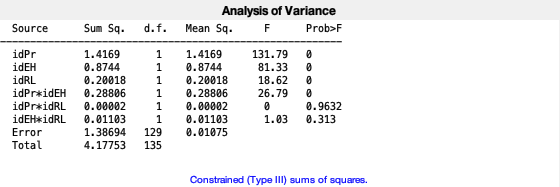


% anova
% matPr=repmat([1;2],[1 nEH length(sessUni)]);
% matEH=repmat([1 2;1 2],[1 1 length(sessUni)]);
% stat=anovan(slope(:),{matPr(:) matEH(:)},'model','interaction','display','on','varname',{'idPr','idEH'});

matPr=repmat([1;2],[1 nEH nTarg length(sessUni)]);
matEH=repmat([1 2],[nPr 1 nTarg length(sessUni)]);
matTarg=repmat(cat(3,1,2),[nPr nEH 1 length(sessUni)]);

stat=anovan(sFull(:),{matPr(:) matEH(:) matTarg(:)},'model','interaction','display','on','varname',{'idPr','idEH','idRL'});

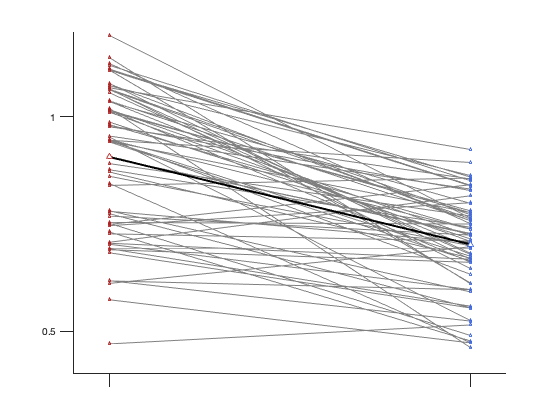



        % new supplementary figure 1 (distribution of slope)
% sS=squeeze(sFull(1,:,:,:)); % EH RL session
tmpMarker={'s','d';'o','^'};

idHist=1; % 0; % 1;
nBin=8;barWidth=0.4;markersize=4;
optsExpFig.Width=3; % 10/2.54;
optsExpFig.Height=3; % 7.3/2.54;

figure; setFigPos(1,1); ha;

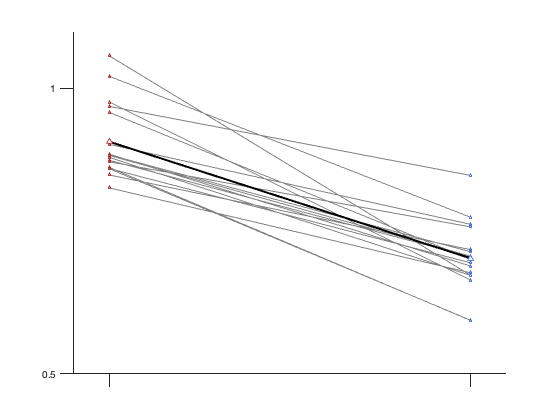

pause(0.1);

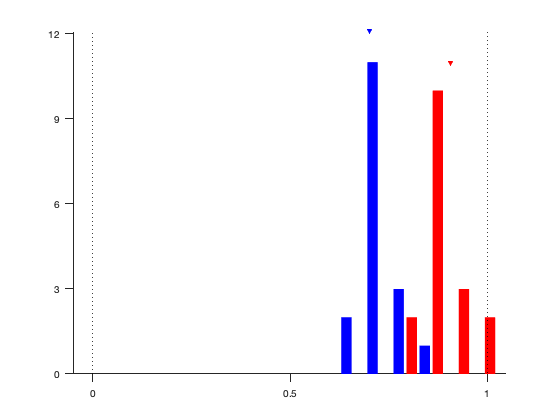

% for iEH=1:nEH
%     for iRL=1:nTarg
% %         figure; setFigPos(iEH,iRL); ha;
%         x=sS(iEH,iRL,:);        y=sL(iEH,iRL,:);
        x=squeeze(mean(mean(sFull(1,:,:,:),2),3)); % sessions by 1
        y=squeeze(mean(mean(sFull(2,:,:,:),2),3));
        
        if idHist
            b=linspace(min([x(:);y(:)]),max([x(:);y(:)]),nBin);
            
            h=histogram(x,b); i=1; % short
            Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
            Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
            hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',pplot.cmap{(i-1)*nPr+1},'EdgeColor','none');
            axis tight; % plot mean
            maxYlim=max(ylim);
            plot(mean(x),1.1*maxYlim,'color',pplot.cmap{(i-1)*nPr+1},'markerfacecolor',pplot.cmap{(i-1)*nPr+1},'marker','v','markersize',markersize);
            
            h=histogram(y,b); i=2; % long
            Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
            Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
            hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',pplot.cmap{(i-1)*nPr+1},'EdgeColor','none');
            axis tight; % plot mean
            maxYlim=max(ylim);
            plot(mean(y),1.1*maxYlim,'color',pplot.cmap{(i-1)*nPr+1},'markerfacecolor',pplot.cmap{(i-1)*nPr+1},'marker','v','markersize',markersize);
            
            plotVertical(gca,0,[]); plotVertical(gca,1,[]);
            
            xlim([-0.05 1.05]);
            set(gca,'xtick',0:0.5:1,'ytick',0:3:20,'tickdir','out','ticklength',[0.02 0.02]);
            pause(0.1);
            
        else % scatter
            plot(x(:),y(:),['k' tmpMarker{iEH,iRL}],'markerfacecolor','w','markersize',markersize);
            axis([-0.1 1.2 -0.1 1.2]);
            plotIdentity(gca);  plotVertical(gca,0,[]); plotVertical(gca,1,[]);plotHorizon(gca,0,[]); plotHorizon(gca,1,[]);
            set(gca,'xtick',0:0.25:1,'ytick',0:0.25:1,'tickdir','out','ticklength',[0.02 0.02]); remTickLabel;
            pause(0.1);
            applytofig(gcf,optsExpFig);
        end

        
        % state
        disp('===== H =====');

===== H =====


        disp([ehNm{iEH} targNm{iRL}]);

HandLeft


        disp('signrank test ignoring conditions');

signrank test ignoring conditions


        disp(['H0(slope(short)<1): ' num2str(signrank(x(:),1,'tail','left'))]);

H0(slope(short)<1): 0.0004604


        disp(['H0(slope(long)<1): ' num2str(signrank(y(:),1,'tail','left'))]);

H0(slope(long)<1): 0.00016052


        disp(['H0(slope(short)>0): ' num2str(signrank(x(:),0,'tail','right'))]);

H0(slope(short)>0): 0.00016052


        disp(['H0(slope(long)>0): ' num2str(signrank(x(:),0,'tail','right'))]);

H0(slope(long)>0): 0.00016052


        disp(['H0(slope(long)<slope(short)): ' num2str(signrank(y(:),x(:)))]);

H0(slope(long)<slope(short)): 0.00029305


%     end % for iRL=1:nTarg
% end % for iEH=1:nEH



disp([]);

## compare bias b/t longest vs shortest ts for each prior

% initially pooled across all sessions/effectors/directions % : issue>for short, bias(shortest ts)>bias(longest ts) % offset? correct by bias at prior mean? didn't work (small like 6) % separate by sessions,effectors

idCompBias=0; % 0; % 0; % 1;

figure; setFigPos(2,3); tmpMarker={'o','d';'^','v'}; % eye/hand x right/left

sessUni=unique(sessId);

mtp=nan(length(sessUni),nEH,nTarg,nPr,2);stp=nan(length(sessUni),nEH,nTarg,nPr,2); offsetMuPr=nan(length(sessUni),nEH,nTarg,nPr);

for iSess=1:length(sessUni) % session data disp(sessUni(iSess)); idSess=sessId==sessUni(iSess);

axis([min([tmpX tmpY]) max([tmpX tmpY]) min([tmpX tmpY]) max([tmpX tmpY])]); plotIdentity(gca); xlabel('mean tp-shortest ts');ylabel('mean tp-longest ts');

% % check correlation b/t offsetMuPr and BLS offset (not separate for EH) % % conclusion: overall correlated % figure; setFigPos(1,1);ha; % plot(offsetMuPr(:,1,1),[wFitSess.offset1],'ro'); % eye short % plotIdentity(gca); % figure; setFigPos(2,1);ha; % plot(offsetMuPr(:,2,1),[wFitSess.offset1],'r^'); % hand % plotIdentity(gca); % figure; setFigPos(1,2);ha; % plot(offsetMuPr(:,1,2),[wFitSess.offset2],'bo'); % eye long % plotIdentity(gca); % figure; setFigPos(2,2);ha; % plot(offsetMuPr(:,2,2),[wFitSess.offset2],'b^'); % hand % plotIdentity(gca);

## SELECT BEST SESSION FOR VISUALIZATION

idExSess=1;
iSess=161218;
if idExSess
    idSess=sessId==iSess; % or 161205
else
    idSess=true(size(sessId));
end

d.ts=T(~idOut & idSess);
d.tp=t(~idOut & idSess);
ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
ipidx=nan(size(ctidx));

## figure 1B: tp vs ts

% close all;
PlotDiff=0; % 1;
% data formatting: [# interval x maxRepetition]
% find max # trials 1st
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        if exist('nMaxTrial')
            nMaxTrial=max([nMaxTrial; nnz(id)]);
        else
            nMaxTrial=nnz(id);
        end
        ipidx(id)=k; % for each trial in d.ts specifies which time bin or ts interval it belongs to. Values: 1-5
    end
end
% filling matrix
Ts=nan(length(Tall),nMaxTrial); % [K x R]
Tp=nan(length(Tall),nMaxTrial);
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial(~idOut & idSess)==(2-i) &... % idShortTrial
            d.ts==Tmat{i}(k); % ts
        Ts((i-1)*nTspp+k,1:nnz(id))=d.ts(id);
        Tp((i-1)*nTspp+k,1:nnz(id))=d.tp(id);
    end
end
d.Ts=Ts;
d.Tp=Tp;
% theory
if idExSess
    idSessTmp=find(unique(sessId)==iSess);
    wm=wFitSess(idSessTmp).w_m;
    wp=wFitSess(idSessTmp).w_p;    
    offset=[wFitSess(idSessTmp).offset2; wFitSess(idSessTmp).offset1];
else
    wm=wFit.w_m;
    wp=wFit.w_p;
    offset=[wFit.offset2; wFit.offset1];
end
for i=1:nPr
    theory{i}.tm=[min(Tmat{i}):max(Tmat{i})]'; % theory{x}.tm - Tx1 - sample corresponding to above
    theory{i}.te=BLS(theory{i}.tm,wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset(i);theory{i}.te=theory{i}.te(:);
    theory{i}.range=1:length(theory{i}.tm);
    theory{i}.wm=wm;
end
DnPlotResponses2P(d,theory,ctidx,ipidx,PlotDiff); % PlotDiff for the last input

% paper
% set(gca,'xtick',400:400:1200,'ytick',400:400:1200,'ylim',[300 1450]); 
if PlotDiff
    axis tight;
    xlim([450 1250]);
    set(gca,'xtick',[480 640 800 1000 1200],'ytick',-300:50:300,'xticklabel',[],'yticklabel',[]);
%     ylim([350 1400]);
    xlabel([]);ylabel([]);
    title([])
    load pplot.mat;
    
    % optsExpFig.Width=5; % 2.6/2.54*2;
    % optsExpFig.Height=5; % 1.9/2.54*2;
    optsExpFig.Format='eps';
    % exportfig(gcf,'tp_ts_H_small.eps',optsExpFig);
    % poster
    optsExpFig.Width=4/2.54; %6.5; % 10/2.54;
    optsExpFig.Height=4/2.54; %6.5; % 7.3/2.54;
    if idExpFig
        savefig(gcf,'tp_ts_H.fig');
        exportfig(gcf,'tp_ts_H.eps',optsExpFig);
    end
else
xlim([450 1250]);
set(gca,'xtick',[480 640 800 1000 1200],'ytick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[]);
ylim([350 1400]);
xlabel([]);ylabel([]);
title([])
load pplot.mat;

% optsExpFig.Width=5; % 2.6/2.54*2;
% optsExpFig.Height=5; % 1.9/2.54*2;
optsExpFig.Format='eps';
% exportfig(gcf,'tp_ts_H_small.eps',optsExpFig);
% poster
optsExpFig.Width=4/2.54; %6.5; % 10/2.54;
optsExpFig.Height=4/2.54; %6.5; % 7.3/2.54;
if idExpFig
    savefig(gcf,'tp_ts_H.fig');
exportfig(gcf,'tp_ts_H.eps',optsExpFig);
end
end

## supplementary figure 1: copy of figure1 for each condition (ER,EL,HR,HL)

---- Eye Right -----
367 trials


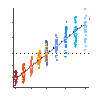

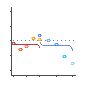

---- Eye Left -----
469 trials


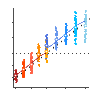

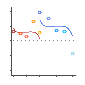

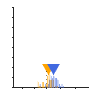

---- Hand Right -----
385 trials


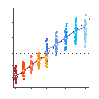

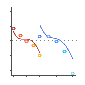

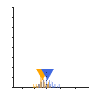

---- Hand Left -----
389 trials


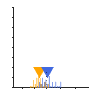

close all;
v=v2struct;
plotSF1(v);

## figure 1C: hist

HsHistTpOverlap(d,ctidx);
% paper
set(gca,'xtick',600:200:1000,'ytick',0:20:20,'tickdir','out'); xlabel([]);ylabel([]);
set(gca,'xticklabel',[],'yticklabel',[]);
load pplot.mat;

% optsExpFig.Width=2; % 2.6/2.54*2;
% optsExpFig.Height=2; % 1.9/2.54*2;
% optsExpFig.Format='eps';exportfig(gcf,'histTpOverlap_H_small.eps',optsExpFig);
% poster
optsExpFig.Width=3; % 10/2.54;
optsExpFig.Height=2; % 7.3/2.54;
if idExpFig
    savefig(gcf,'histTpOverlap_H.fig');
exportfig(gcf,'histTpOverlap_H.eps',optsExpFig);
end

## supplementary figure 2: bias-var (BLS), data vs model

now session-specific (line data-model, filled for model, circle for data) wFitSessCond: 17sess x 2EH x 2RL: w_m, w_p, offset1(long), offset2

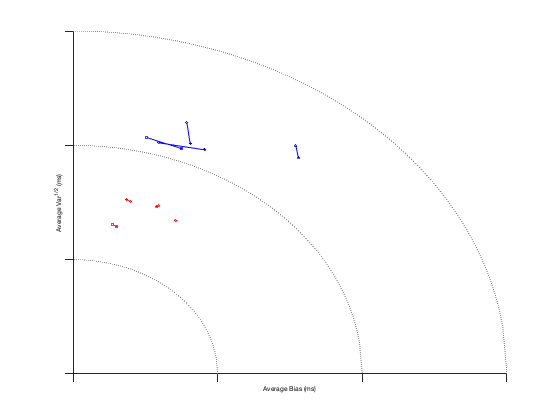

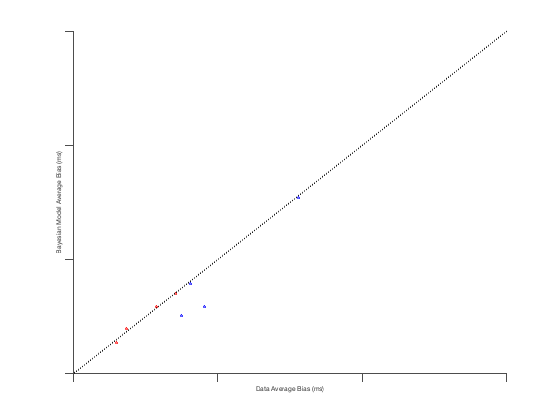

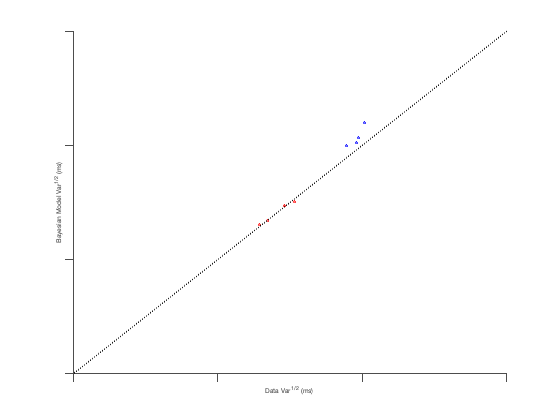

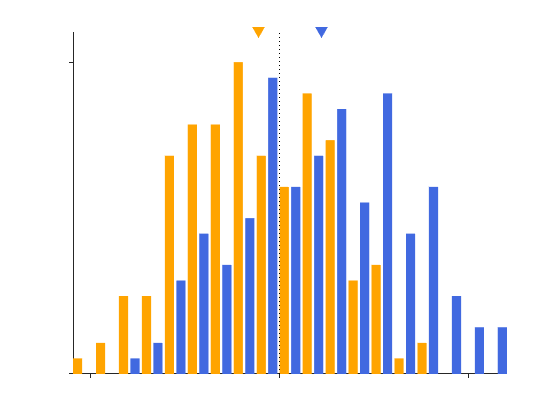

EyeRight


EyeLeft


HandRight


HandLeft


EyeRight


EyeLeft


HandRight


HandLeft


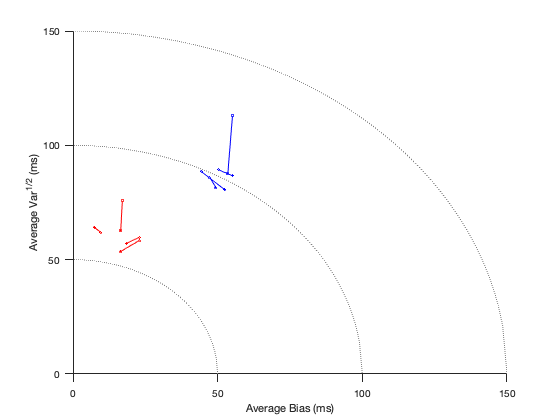

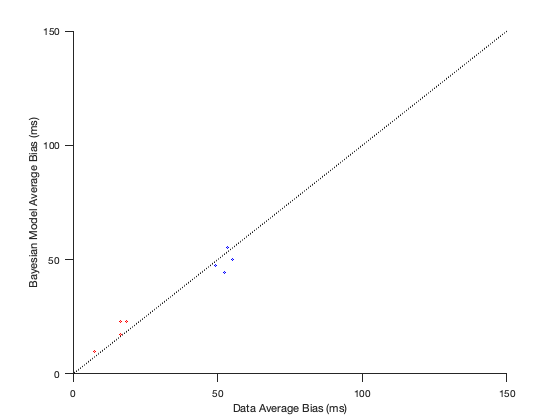

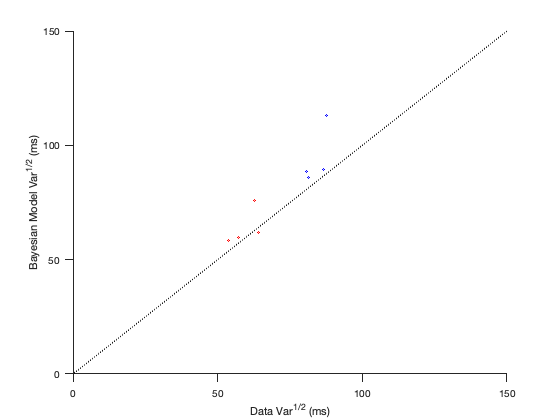

HsPlotBiasVar2; % (sessId,idHandEye,theta,T,t,idShortTrial,wFitSessCond,idOut);

## figure 1D: bias variance

dBLS.wm=wm; % wFit.w_m;
dBLS.wp=wp; % wFit.w_p;
dBLS.offset1=offset(2); % wFit.offset1; % for long
dBLS.offset2=offset(1); % wFit.offset2;
% with offset, discrepancy is lower; TBD: model comparison with prior-dependent wm,wp
HsPlotBiasVar(d,ctidx,dBLS);

set(gca,'xtick',0:50:150,'ytick',0:50:150,'tickdir','out','ticklength',[0.03 0.03]); xlabel([]);ylabel([]);

load pplot.mat;
optsExpFig.Width=2.6/2.54;optsExpFig.Height=1.9/2.54;
optsExpFig.Format='eps';
if idExpFig
    exportfig(gcf,'biasVar_H.eps',optsExpFig);
end
% % poster
% optsExpFig.Width=10/2.54;optsExpFig.Height=7.3/2.54;
% exportfig(gcf,'biasVar_H_large.eps',optsExpFig);

## stat for overlap

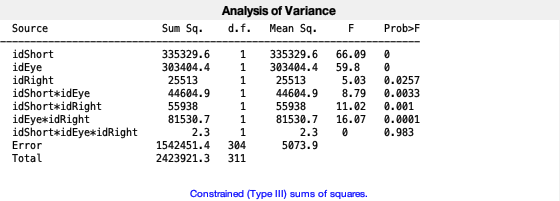

idAbort=t<0;
idNoResp=t>3*T;
idValid=t>0&t<3*T;

% anova with new outlier selected
overlapT=800; 
tmpId=~idOut & idSess &T==overlapT;
stat=anovan(t(tmpId),{idShortTrial(tmpId) idHandEye(tmpId) theta(tmpId)/180},'model',3,'display','on','varnames',{'idShort' 'idEye' 'idRight'});


idPlot=0; % 1;
for i=1:nPr
    for j=1:nEH
        for k=1:nTarg
            id=idShortTrial==(2-i) &... % idShortTrial
                idHandEye==(2-j) &...  % idHandEye
                theta==(k-1)*180 &... % target location
                T==overlapT &...
                ~idOut;
            
            disp([prNm{i} ',' ehNm{j} ',' targNm{k} num2str(mean(t(id)))]);
            
            if idPlot
                figure; set(gcf,'position',pplot.(['rect' num2str(i) '_' num2str((j-1)*nTarg+k)]));hold all;
                histfit(t(id),35); axis tight; plotHorizon(gca,mean(t(id)),[]);
                title([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', overlap, \mu&SD: ' num2str(meanSD(t(id))) ' ms']);
                disp([prNm{i} ', ' ehNm{j} ', ' targNm{k} ', overlap, \mu&SD: ' num2str(meanSD(t(id))) ' ms']);
                xlim([400 1200]);
            end
            
        end % for k=1:nTarg
    end % for j=1:nEH
        id=idShortTrial==(2-i) &... % idShortTrial
        T==overlapT &...
        ~idOut;
    disp([prNm{i} ', overlap, \mu&SD: ' num2str(meanSD(t(id))) ' ms']);
end % for i=1:nPr

Short,Eye,Right814.6311
Short,Eye,Left824.9032
Short,Hand,Right780.7902
Short,Hand,Left755.7929


Short, overlap, \mu&SD: 793.8593 ms


Long,Eye,Right825.1375
Long,Eye,Left840.8047
Long,Hand,Right842.055
Long,Hand,Left813.1701


Long, overlap, \mu&SD: 830.4039 ms


## sFig1. 3/5/2018: switching across blocks (bias=f(trials after switch), only overlap?

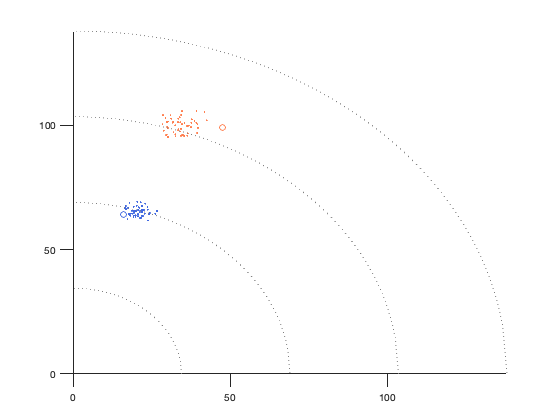

% 12/6, 12/7, part of 12/10 [1 3 15] used one-trial block
sessTBT=[161206; 161207; 161210];
for iSess=1:length(sessTBT)
    idOut(sessId==sessTBT(iSess))=true;
end % for iSess=1:length(sessTBT)

% identifying condition: prior(S/L) by effector (E/H) 
% 1234: shortE>shortH>longE>longH
idC=(2-idShortTrial-1)*nEH+(1-idHandEye)+1; % [32839 x 1] 1234:shorteye/shorthand/longeye/longhand
idTSw=[true;[(abs(diff(idC))>0)|(diff(sessId)~=0)]]; % 1 for the trial after switchn
iTSw=idC(idTSw); % [6507 blocks x 1]
idBlock=cumsum(idTSw); % [11112222...]
idComplete=(t<3*T & t>0);

normTp=(t-T)./T;
idOverlap=(T==Tmat{1}(end));

nBlock=max(idBlock);
normTp2=[]; % cell(1,nBlock);
idOverlap2=[]; % cell(1,nBlock);
idOut2=[]; % cell(1,nBlock);
idSwPr=[]; % -1 long2short, 1 for short2long, ignoring EH switch
iSwPr=1;
for iB=1:nBlock
    % only considering # trials(complete)
%     normTp2{iB}=normTp(idBlock==iB & idComplete); %[trial/block x 1]
%     idOverlap2{iB}=idOverlap(idBlock==iB & idComplete);
%     idOut2{iB}=idOut(idBlock==iB & idComplete);
    if iB==1 % assume transition
        if iTSw(iB)<=2 % short
            idSwPr=-1; % -1 long2short
        else
            idSwPr=1;
        end
        normTp2{iB}=normTp(idBlock==iB & idComplete); %[trial/block x 1]
        idOverlap2{iB}=idOverlap(idBlock==iB & idComplete);
        idOut2{iB}=idOut(idBlock==iB & idComplete);
    else
        if iTSw(iB-1)<=2 & iTSw(iB)>2 % short2long
            idSwPr=[idSwPr;1];iSwPr=iSwPr+1;
            normTp2{iSwPr}=normTp(idBlock==iB & idComplete); %[trial/block x 1]
            idOverlap2{iSwPr}=idOverlap(idBlock==iB & idComplete);
            idOut2{iSwPr}=idOut(idBlock==iB & idComplete);
        elseif iTSw(iB-1)>2 & iTSw(iB)<=2 % long2short
            idSwPr=[idSwPr;-1];iSwPr=iSwPr+1;
            normTp2{iSwPr}=normTp(idBlock==iB & idComplete); %[trial/block x 1]
            idOverlap2{iSwPr}=idOverlap(idBlock==iB & idComplete);
            idOut2{iSwPr}=idOut(idBlock==iB & idComplete);
        else % appending to previous blocks (changing EH/session w/o changing prior)
            normTp2{iSwPr}=[normTp2{iSwPr};normTp(idBlock==iB & idComplete)]; %[trial/block x 1]
            idOverlap2{iSwPr}=[idOverlap2{iSwPr};idOverlap(idBlock==iB & idComplete)];
            idOut2{iSwPr}=[idOut2{iSwPr};idOut(idBlock==iB & idComplete)];
        end
    end
end % iB=1:max(idBlock)

nTpB=cellfun(@length,normTp2);

normTp2=fillNanCell(normTp2); % fillNanCell accepts cells of vectors [6507 blocks x 26 trials]
idOverlap2=fillNanCell(idOverlap2);
idOverlap2(idOverlap2~=1)=nan;idOverlap2(idOverlap2==1)=0;
idOut2=fillNanCell(idOut2); % 
idOut2(idOut2==1)=nan; % nan if outlier

% plot w/ avg
trial=0:(size(normTp2,2)-1);
% 1) normTp2 w/o outlier: all trials
figure; setFigPos(1,2); ha;

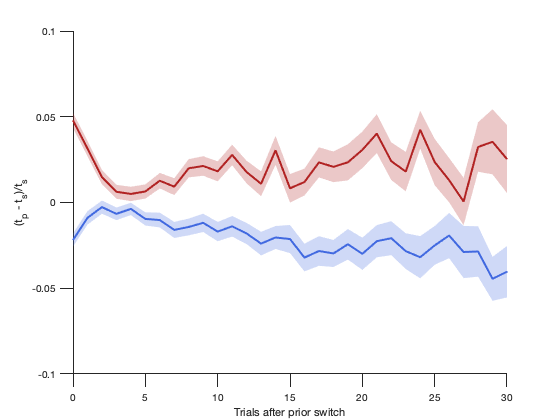

iSwPr=unique(idSwPr); % -1 1
for iSw=1:length(iSwPr) % short2long vs long2short
    normTp2woOut=normTp2(idSwPr==iSwPr(iSw),:)+idOut2(idSwPr==iSwPr(iSw),:); % nan if outlier
    mNormTp2=nanmean(normTp2woOut,1);
    semNormTp2=sem(normTp2woOut,0,1,'omitnan');
    shadedErrorBar(trial,mNormTp2,semNormTp2,{'-','color',tmpCmap{iSw,1}(1,:),'linewidth',2},1); drawnow;
end
nTrialEnd=30;
set(gca,'xlim',[0 nTrialEnd],'ylim',[-0.1 0.1],'ytick',[-0.1:0.05:0.1],'tickdir','out','ticklength',[0.03 0.03]);
xlabel('Trials after prior switch'); ylabel('(t_p - t_s)/t_s');

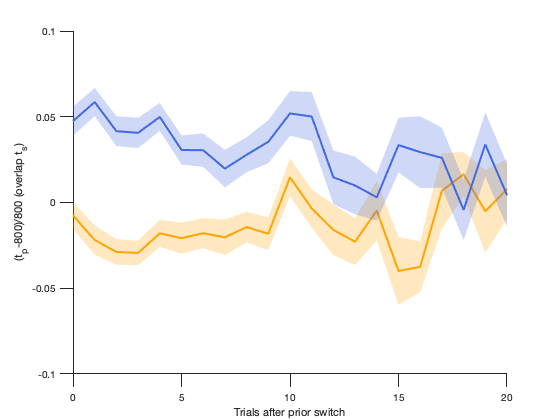


% 2) normTp2 w/o outlier: only overlap trials
figure; setFigPos(1,3); ha;
for iSw=1:length(iSwPr) % short2long vs long2short
    normTp2woOut=normTp2(idSwPr==iSwPr(iSw),:)+idOut2(idSwPr==iSwPr(iSw),:)+idOverlap2(idSwPr==iSwPr(iSw),:); % nan if outlier
    mNormTp2=nanmean(normTp2woOut,1);
    semNormTp2=sem(normTp2woOut,0,1,'omitnan');
    shadedErrorBar(trial,mNormTp2,semNormTp2,{'-','color',tmpCmap{iSw,1}(nTspp-(nTspp-1)*(iSw-1),:),'linewidth',2},1); drawnow;
end
nTrialEnd=20;
set(gca,'xlim',[0 nTrialEnd],'ylim',[-0.1 0.1],'ytick',[-0.1:0.05:0.1],'xtick',[0:5:nTrialEnd],'tickdir','out','ticklength',[0.03 0.03]);
xlabel('Trials after prior switch'); ylabel('(t_p-800)/800 (overlap t_s)');

## BLS fit for each sessions

for now, wm, wp common for all condition (prior, ts, modality, directions) & offset separately for prior model comparion to be done: promising (offset,wp separate for modality)

% sidUni=unique(sessId);
% bicSess=[];wFitSess=[];
% for iS=1:length(sidUni)
%     disp(['===== ' num2str(sidUni(iS)) ' =====']);
%     idS=sessId==sidUni(iS);
%     id=idS&~idOut;
%     
%     [wFitTmp,bicTmp]=estWmWpOld(t(id),T(id),idShortTrial(id),'mmse2offset',[],-1,true); % display: off
%     fieldnm=fieldnames(wFitTmp);
%     for j=1:length(fieldnm)
%         wFitSess(iS).(fieldnm{j})=wFitTmp.(fieldnm{j}); % mmse2offset: w_m w_p offset1 offset2
%     end
%     bicSess=[bicSess; bicSess];
%     disp([wFitTmp.w_m(:) wFitTmp.w_p(:) wFitTmp.offset1(:) wFitTmp.offset2(:)]);
% save([behDir 'H_RSGprior_DMFC.mat'],'wFitSess','bicSess','-append');
% 
% end
% 
% % also BLS fit for pooled data
% analHandEye2PriorRSG('H_RSGprior_DMFC.mwk');

## check across-session variability of wm,wp,offset (wFit w/ outlier removal)

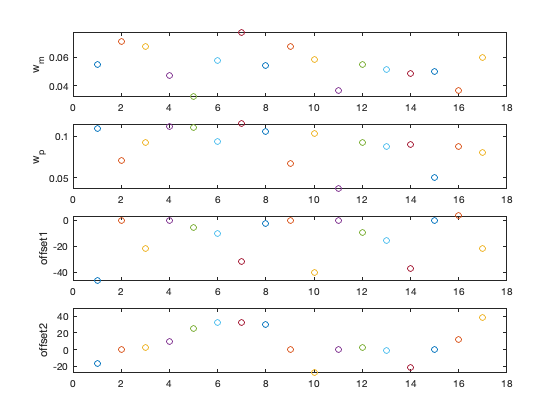

figure; setFigPos(2,3); nMeas=4; 
load([behDir 'H_RSGprior_DMFC.mat']); % T t idShortTrial idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)

for iS=1:length(wFitSess)
    subplot(nMeas,1,1);plot(iS,wFitSess(iS).w_m,'o'); ylabel('w_m');hold all;
    subplot(nMeas,1,2);plot(iS,wFitSess(iS).w_p,'o'); ylabel('w_p');hold all;
    subplot(nMeas,1,3);plot(iS,wFitSess(iS).offset1,'o'); ylabel('offset1');hold all;
    subplot(nMeas,1,4);plot(iS,wFitSess(iS).offset2,'o'); ylabel('offset2');hold all;
end


disp('check offset is needed (long,short)')

check offset is needed (long,short)


p=signrank([wFitSess.offset1])

p = 0.0049

p=signrank([wFitSess.offset2])

p = 0.0759

## te

load pplot.mat; % simulation nT=10000; wm=0.07; tsS=[480:80:800]; tsL=[800:100:1200]; ts={tsS;tsL};

varTe=nan(size(cell2mat(ts))); % [2 x 5] skewTe=nan(size(cell2mat(ts))); % [2 x 5] h=figure;ha; for iPr=1:2 T=repmat(ts{iPr},1,nT);T=T(:); Tm=randn(size(T)) .* (wm.*T) + T; %noise te=BLS(Tm,wm,[min(ts{iPr}) max(ts{iPr})],'uniform'); % BLS plotTpTs(T,te,1,pplot.cmap{(iPr-1)*2+1},h,'-',1000); % last for nSD for iTs=1:length(ts{iPr}) id=ts{iPr}(iTs)==T; figure; set(gcf,'position',pplot.(['rect' num2str(iPr) '_' num2str(iTs)])); histfit(te(id),35); varTe(iPr,iTs)=var(te(id)); skewTe(iPr,iTs)=skewness(te(id)); end end figure(h); xlabel('t_s'); ylabel('t_e'); axis tight; plotIdentity(gca); plotWeberLine(gca,0.2);ylim([480 1250]);

figure; ha; % var(te) plot(tsS,varTe(1,:),'r-');plot(tsL,varTe(2,:),'b-'); xlabel('t_s'); ylabel('var(t_e)'); axis tight;

figure; ha; % skew(te) plot(tsS,skewTe(1,:),'r-');plot(tsL,skewTe(2,:),'b-'); xlabel('t_s'); ylabel('skewness(t_e)'); axis tight;

## define D data structure

tSort=sort(t(t>0));tB=tSort([1 round([(1/nTp):(1/nTp):1]*length(tSort))]); % 0 0.2 0.4 ... 1 tLong=sort(t(idShortTrial==0&t>0));tLB=tLong([1 round([(1/nTp):(1/nTp):1]*length(tLong))]); % 0 0.2 0.4 ... 1 tShort=sort(t(idShortTrial==1&t>0));tSB=tShort([1 round([(1/nTp):(1/nTp):1]*length(tShort))]); % 0 0.2 0.4 ... 1

## session-pooled outlier removal

% 2 prior x 2 modality x 2 direction ANOVA for overlap ts % after remove outliers (2 SD) for each combination idPlot=1; nSDremoveOutlier=2; overlapT=800; tMat=[];iPr=[];iEH=[];iRL=[]; for i=1:nPr for j=1:nEH for k=1:nTarg id=idShortTrial==(2-i) &... % idShortTrial idHandEye==(2-j) &... % idHandEye theta==(k-1)*180 &... % target location T==overlapT &... t>0 & t<3*overlapT; % only valid trials for now u0=[0.5 1.5]*overlapT; %[0.1 1.9]*overlapT; % [0.5 1.5]*overlapT; %[0 2]*overlapT; % with least outlier removal; or max(t) [tClean,idClean,pOut,tOut]=removeOutlier(t(id),0,u0); %nSDremoveOutlier); tMat=[tMat;tClean(:)]; iPr=[iPr; repmat(prNm(i),[nnz(tClean) 1])];iEH=[iEH; repmat(ehNm(j),[nnz(tClean) 1])];iRL=[iRL; repmat(targNm(k),[nnz(tClean) 1])];

return;

## old init

try
    cd('/Users/hansem/Dropbox (MIT)/figuresRSG2prior/1beh'); % SFN17/1beh'); % CCN17/beh');
    behDir='/Users/hansem/Dropbox (MIT)/fileFromNHPrig/dataMat/';
    neuDir='/Users/hansem/Dropbox (MIT)/fileFromNHPrig/neuralData/';
    psthDir='/Users/hansem/Dropbox (MIT)/psthDataHigh/';
    dirName='/Users/hansem/Documents/Recording/'; % cd(dirName);

catch
    cd('/Users/seonminahn/Dropbox (MIT)/figuresRSG2prior/1beh'); % CCN17/beh');
    behDir='/Users/seonminahn/Dropbox (MIT)/fileFromNHPrig/dataMat/';
    neuDir='/Users/seonminahn/Dropbox (MIT)/fileFromNHPrig/neuralData/';
    psthDir='/Users/seonminahn/Dropbox (MIT)/psthDataHigh/';
    dirName='/Users/seonminahn/Documents/Recording/'; % cd(dirName);
end


fname={...
%     'H_RSGprior_20161202';... % only eye; use 003
    'H_RSGprior_20161203';... % no photosync; RSG>overlap>RSG; use 003
    'H_RSGprior_20161204';... % no photosync
    'H_RSGprior_20161205';... % no photosync; no overlap
    'H_RSGprior_20161206';...
    'H_RSGprior_20161207';...
    'H_RSGprior_20161208';... 
    % 2nd craniotomy @12/9 afterward, [5 3 20]
    'H_RSGprior_20161210';...
    'H_RSGprior_20161211';...
    'H_RSGprior_20161212';...
%     'H_RSGprior_20161213';...
    'H_RSGprior_20161214';...
    'H_RSGprior_20161215';... 
    % 3rd craniotomy @12/16
    'H_RSGprior_20161218';...
    'H_RSGprior_20161219';...
    'H_RSGprior_20161220';...
    'H_RSGprior_20161221';...
    'H_RSGprior_20161222';... % saved as 12/21
    'H_RSGprior_20161223'
    };
nS=length(fname);



load pplot.mat;

## relevant cell list [electrode ID, unit ID(12345), start trial, end trial]: liberal criteria for trials

TBD: check all units

cname={...
%     [29 1 1 1658; 21 1 562 1230; 21 2 562 1230];... % %     'H_RSGprior_20161202';... % only eye; use 003
    [15 1 1 1297; 8 1 1 1297; 9 1 1 1297; 21 1 599 1297; 27 1 616 1297; 25 1 600 1297];... %     'H_RSGprior_20161203';... % no photosync; RSG>overlap>RSG; use 003
    [3 2 1 1830; 11 1 309 1628; 9 3 857 1830;29 2 804 1830;5 3 1116 1830;31 1 1 576;10 2 1490 1830;11 2 857 1830;12 3 1294 1830; 23 1 1294 1830];... %     'H_RSGprior_20161204';... % no photosync
    [4 1 208 1315; 13 4 1 2238; 17 4 572 1483;23 1 1280 2238;8 1 1 1806; 8 4 1 1806;10 1 1 1505;6 1 714 1236;4 2 902 1315;11 4 1 2238;13 1 1 2238;14 1 1 1117;16 1 1 1000;21 2 1785 2238;19 1 1785 2238;];... %     'H_RSGprior_20161205';... % no photosync; no overlap
    [6 1 1 2797;15 1 1 2029;19 1 1 2797;29 4 1 699; 29 5 1 1904;4 1 1 2797; 53 1 1 750;51 4 1 1698;4 2 439 2739;44 1 1 1309;45 4 1 2472;1 1 535 2797;29 5 579 2797;10 4 1 1725;55 1 660 1553;8 1 1 2050;11 1 830 2383; 14 2 830 1748; 19 2 661 2439; 21 1 868 1587;48 2 923 1594; 42 1 1459 2058;48 1 1637 2797;12 1 1 2394;25 1 1776 2328;2 1 1841 2575;48 3 2224 2797;9 5 1 2773;16 4 2420 2797;31 4 1 2797;57 1 1 2541];... %     'H_RSGprior_20161206';...
    [11 1 1 1993-800;15 4 1 1711;19 4 1 1711;21 4 1 1711;21 5 1 1711;23 1 1 1711;23 2 1 1711;25 4 1 1711;4 1 1 2346-800;4 4 1 1711;6 4 1 1711;14 1 1 1711;41 2 1 1711;43 1 1 1711;43 4 1 1711;43 2 1523-800 1711;45 4 926-800 1711;47 1 1 1711;47 2 1 1711;47 4 1 1711;49 4 1 1711;53 4 1 1711;55 1 1 1711;59 1 154 1711; 61 1 1 1711;63 1 1 1711;34 1 1 1711;36 4 1 1711;44 4 1 1711;48 4 1 1711];... %     'H_RSGprior_20161207';...
    [29 1 1 1711;31 1 1 1711;34 4 1 1711;34 5 1 1711;55 4 1 1711;55 5 1 1711;57 1 1 1711;57 2 1 1711;59 1 1 1711;59 2 1 1711;63 1 1 1711;63 4 1 1711;66 1 1 1711;68 1 302 1711;68 2 1425 1711;75 1 1 1711;81 1 1 1711;81 2 1 1711;81 3 1 1711;83 4 415 1711;89 1 1 1711];... %     'H_RSGprior_20161208';... 
    %     % 2nd craniotomy @12/9 afterward, [5 3 20]
    [5 4 198 1546;11 4 1 1546;11 5 1 1546;16 1 1 1546;16 2 1 1546;33 4 180 1546;33 5 180 1546;67 1 1 1420;67 2 1 1420;71 1 1 1546;73 1 1 1430;73 2 1 1430;76 1 1178 1546;79 1 1 1546;79 2 1 1546;81 1 1 1420;66 1 1 1420];... %     'H_RSGprior_20161210';...
    [1 1 1 1774;1 2 1 1774;3 1 1 1774;5 1 1 1774;5 3 1441 1774;7 1 1 1774;7 2 1 1774;9 4 1 1774;13 1 105 1774;15 4 1 1774;17 1 1 1774;19 1 1 1774;21 1 1 1774;21 2 1 1774;23 1 1 1774;27 1 1 1774;29 1 1 1774;31 1 1 1774;2 4 224 1774;4 1 1 1774; 4 2 1 1774;6 1 1 814;6 2 1 1774;8 4 1 1774;10 4 1 1774;12 2 1 1774;12 3 961 1774;14 1 1 1745; 16 1 1 854;16 4 1 1774;51 1 1 1774;53 1 1 1774;53 2 1152 1774;55 1 1 320;55 2 1 320;55 3 320 904;57 1 375 910;61 1 334 1526;61 4 1 1774;44 1 1 1774;68 1 1 1541;69 4 1 1774;69 5 1 1774;79 1 1 1774;81 1 1 1774;85 4 1 1774;85 5 1 1774;87 4 1 1774;87 5 1 1774;89 1 1 394;93 1 1 1774;95 1 1 1774;66 4 1 1774;66 5 1 1774;70 1 1 1774;72 1 1 794];... %     'H_RSGprior_20161211';...
    [7 1 1 1524;21 4 1 1524;21 5 1 1524;10 4 1 1524;33 4 1 1524;33 5 1 1524;35 4 1 1524;37 4 1 1524;37 5 1 1524;67 1 1 1367;75 4 1 1524;75 5 1 1524;79 4 1 1524;79 5 1 1524;87 4 1 1524;87 5 1 1524];... %     'H_RSGprior_20161212';...
%     [4 1 1 1287;8 4 1 1847;10 1 1 1847;43 4 1 1847;37 1 514 1847;38 1 1 730;38 2 1 1847;38 3 1 1847;40 1 1 1847;42 1 1 1847;42 2 245 1847;44 1 1 1847;48 1 1 1847;48 2 1 1847;48 3 1 1847;48 4 1 1847;85 4 1 1847;87 4 1 1847;87 5 1 1847];... % %     'H_RSGprior_20161213';...
    [48 4 1 210;46 4 221 1761;46 2 229 1761;44 1 116 1761;44 2 249 1761;44 3 249 1761;38 1 82 1761;34 1 178 1761;36 1 1 1761;47 1 338 1706;42 1 1 1761;42 4 1 1761;40 1 1 1761;37 1 1 1761;41 1 310 1761;41 2 371 1761;41 3 391 1761;48 1 1 1761;48 2 1 1761;48 3 526 1761;48 4 17 1761;46 2 229 1761;46 3 1 1761;46 4 221 1761;44 1 1 825;44 1 825 1761;44 2 1 825;44 2 825 1761;44 3 1 1761;44 4 1 1761;44 5 1 1761;42 1 1 1761;42 4 1 1761;42 5 1 1761;40 1 1 1761;40 2 549 1761;40 3 766 1761;38 4 1 1761;38 5 1 1761;38 1 1 1761;36 1 1 1222;36 2 707 1761;36 4 1 1761;36 5 1 1761;34 1 178 1761;34 4 1 1761;34 5 476 1761;34 2 996 1761;63 1 485 1761;57 1 627 1552;53 1 1 1538;49 4 1 1761;47 1 1 1495;47 4 1 1761;45 1 1 1761;45 3 1 1761;43 1 1 1761;41 1 1 1761;39 1 1 1761;37 4 1 1761;37 5 1 1761;35 1 1 1761;35 4 1 1761;33 4 581 1761;61 2 1016 1561;55 1 1422 1761;55 2 1422 1761];... %     'H_RSGprior_20161214';...
    [31 1 250 1597;31 3 1 1597;29 4 1 1597;29 5 1 1597;27 4 1 1597;27 5 262 1597;25 4 1 1193;25 1 1193 1466;25 2 1208 1597;23 4 1 1597;21 1 1 1597;21 4 1 1597;19 2 98 425;17 1 325 1597;15 1 1 1597;15 2 430 1597;13 4 436 1597;9 4 1 1597;7 1 1 1597;5 2 1 1597;5 4 1 1597;3 1 1 1597;1 2 1 475;1 1 475 1438;1 3 475 1438;16 2 1 1597;16 4 1 1597;14 2 1 1597;14 3 743 1319;14 4 1 1597;12 2 1 1597;12 3 1 1597;12 4 214 1597;10 4 1 1597;10 5 1 1597;8 1 1 1597;8 2 1 1597;6 1 185 1597;6 5 970 1597;6 4 1 970;4 1 1 1597;4 4 1 1597;4 5 1 1597;2 1 1 1597];... %     'H_RSGprior_20161215';... 
    % 3rd craniotomy @12/16
    [1 1 1 2097;5 4 1 2097;7 4 1 2097;9 1 1 2097;11 1 1 2097;13 1 1 2097;15 1 1 2097;15 2 1 314;15 4 21 2097;17 1 1268 2097;17 4 1 2097;17 5 1 2097;19 1 60 2097;21 1 1 2097;21 4 1 2097;23 4 1 2097;25 1 1 2097;25 2 1 2097;27 1 1 2097;27 2 1 2097;29 1 1 2097;29 2 1 2097;29 4 1 2097;31 4 118 2097;31 1 1 1192;4 4 1 369;4 1 369 985;12 1 1 2097;12 2 1 2097;14 1 632 2097;14 4 1 2097;14 5 1 2097;16 1 519 2097;16 2 1 2097;16 3 50 2097;2 4 1 2097;8 4 1 2097;8 1 1652 2097;10 1 1 2097;10 2 1 2097;10 3 1 2097;6 4 1670 2097;6 5 1670 2097;47 1 1 2097;47 2 1 1951;49 4 1 2097;51 1 1 2097;53 4 444 2097;55 1 1 2097;55 4 1 2097;57 1 1 2097;59 1 1 2097;61 1 1 2097;63 4 1 2097;34 1 146 2097;34 4 1 2097;36 1 164 2097;36 4 1 2097;38 1 238 2097;38 4 1 2097;42 1 249 2097;42 4 249 2097;44 1 1 2097;44 4 270 2097;44 2 672 2097;48 4 1 2097;48 5 1 2097];... %     'H_RSGprior_20161218';...
    [1 4 1 1591;3 4 108 1591;13 1 117 1591;15 4 1 1591;15 4 1 1591;17 4 148 1591;19 4 1 1591;21 1 1 1591;23 2 1386 1591;23 1 1 1591;23 4 794 1591;25 1 164 1591;27 1 1 1591;27 2 237 1591;29 4 825 1591;31 1 1 1591;2 4 1 1591;4 4 180 1591;4 5 192 643; 4 1 643 1065;4 2 643 1315;4 3 643 1591;6 4 1 1591;8 1 1 1591;10 1 360 1591;12 4 1 1591;12 5 1 1591;14 1 1 1355;14 2 1355 1591;14 4 1 1591;16 1 368 1591;16 4 1 1591;35 1 1 1591;37 1 1 1591;39 1 1 1591;41 1 1 1591;43 4 1 1591;45 1 92 1591;45 4 382 1591;47 1 1 1591;49 4 300 1197;34 4 877 1591;36 1 1 1591;36 2 1 1591;38 1 1 1591;40 1 1 1591;40 4 400 1591;44 4 1 1591;46 1 211 1591;48 4 1 1591;48 5 250 1591;];... %     'H_RSGprior_20161219';...
    [1 1 1 1312;1 2 677 1312;3 1 82 1304;3 4 1 1791;5 1 1295 1791;7 4 1 1791;9 4 1 1791;11 4 1 1791;13 4 1 1791;15 1 517 1791;15 4 1 1791;17 4 470 1791;17 5 470 1791;19 4 1 1791;23 1 1481 1791;25 1 703 1230;25 2 795 1230;25 4 1 1791;27 1 30 1791;29 4 1 1791;29 5 1215 1791;31 1 459 1204;4 1 1 1170;4 4 1 1791;4 5 1 1791;2 1 1 1791;2 2 141 1191;2 4 1 1791;6 1 1 1791;6 2 1 1791;6 3 780 1791;6 4 1327 1791;8 4 309 1103;8 5 320 1791;8 1 1 1791;10 4 1 1791;10 5 1 1791;12 1 1 1791;12 2 1 1791; 12 3 565 1791;12 4 1139 1791;12 5 1327 1791;14 1 1 1791;14 2 1 1791;14 3 530 1791;16 1 481 878;16 2 1 878;16 4 1 1791;14 5 638 1791;16 3 651 1791;10 1 1504 1791;8 2 1580 1791;8 2 1580 1791;39 4 1 1791;41 4 1 1791;43 4 1 1791;45 4 1 1791;47 4 1 1791;49 1 1 1462;49 4 1 1791;51 4 1 1565;53 4 1 1791;55 4 253 1477;57 1 352 1477; 57 4 1 1791;59 4 367 1714;61 1 1 602;61 4 1 1597;61 5 1 1597;63 1 1 1597;63 2 267 1597;34 1 1 1608;34 2 1 1608;36 4 1 1791;36 5 1 1791;40 1 219 1791;40 4 1 1791;38 1 1 1791;42 4 1 1791;42 5 1 1791;44 4 1 1791;44 5 228 1067;46 4 1 1791;46 2 932 1791;46 5 1 1791;46 1 913 1791;48 1 1 1791;48 2 1 1791;48 4 1 1791];... %     'H_RSGprior_20161220';...
    [13 5 1 2139;13 4 345 2139;15 3 379 1229;15 1 379 1229;15 2 379 1229;17 4 1 2139;19 4 1 2139;19 1 1308 2139;19 2 1308 2139;21 1 1 2139;21 2 138 1411;21 3 1411 2139;21 4 1 2139;21 5 1 2139;23 1 1 1319;23 2 1 1319;23 4 1 1319;25 4 1 2139;27 1 1 2139;29 1 1 2139;31 4 1 2139;31 1 156 2139;31 2 156 2139;2 1 1 2139;2 2 104 2139;21 4 1 2139;4 1 1 1654;4 2 1654 2139;6 1 1 2139;6 2 1 2139;8 1 1 2139;8 2 1 2139;8 3 1 2139;10 1 1 2139;10 2 1 2139;12 1 1 2139;12 2 1 2139;12 4 1 2139;14 2 1 2139;14 3 1 2139;14 4 1 2139;16 1 1 2139;16 2 412 2139;16 4 1 2139;33 4 1 2139;35 4 1 2139;37 4 1 2139;39 1 1339 2139;39 4 1 2139;39 5 1 2139;41 1 1 2139;41 2 1 2139;43 1 91 2139;43 4 1 2139;45 3 1877 2139;45 1 1 1733; 45 4 1 2139;45 2 1746 2139;47 1 1 2139;49 4 951 2139;51 1 1 2139;55 4 1 2139;57 4 1 2139;34 4 1 2139;34 5 1 2139;36 4 1 2139;38 4 1 2139;40 4 130 2139;42 4 1 2139;44 1 841 2139;44 4 1 2139;44 5 1 2139;46 1 1 2139;46 2 1600 2139;46 4 1 2139;48 2 1 2139;48 1 1050 2139;48 3 1050 2139;48 4 1 2139;];... %     'H_RSGprior_20161221';...
    [1 1 1 2158;1 2 1 2158;3 4 1 2158;13 2 139 2158;13 1 1 2158;15 1 1 2158;15 2 1839 2158;15 4 1 2158; 17 1 1 2158;21 1 1 2158;21 4 1 2158;21 5 1 2158;23 1 1 2158;23 2 1986 2158;25 1 1 2158;25 4 1 2158;27 1 617 2158;27 4 1 2158;29 4 1 2158;31 1 1 2158;31 2 1 2158;31 4 1 2158;2 1 1 2158;2 2 92  2158;2 4 1 2158;4 1 1 1706;4 4 1 2158;6 1 1 2079;6 4 1 2158;8 4 1 2158;10 1 1 2158;10 4 1 2158;12 1 1 2158;12 2 1 2158;12 3 1720 2158;14 1 1 2158;14 2 1 2158;14 4 1 2158;16 2 1 1328;16 1 1328 2158;16 3 1 2158;33 4 1 2158;35 1 1 2158;35 2 1 2158;35 3 1 2158;37 1 1 2158;39 1 1 2158;39 2 1 2158;41 1 1 2158;43 1 1 2158;45 4 196 2158;47 1 1 2158;49 4 1 2158;51 1 1 2158;51 4 1 2158;53 1 233 2158;55 4 246 2158;57 1 1 2158;61 1 1 2158;61 4 1 2158;63 4 258 2158;34 4 867 2158;36 1 1 2158;36 4 1 2158;38 4 1 2158;40 4 1 2158;40 5 1 2158;42 1 1 2158;44 1 1 2158;44 2 650 2158;46 1 209 1177;46 2 202 2158;46 4 1 2158;48 4 1 2158; 48 1 1191 2158;];... %     'H_RSGprior_20161222';... % saved as 12/21
    [1 1 1 2477;3 1 1 2477;3 4 1 2477;3 2 1588 2477;3 3 2212 2477;13 1 779 2477;13 4 1 2477;15 1 1 2477;15 4 1 2477;17 4 1763 2477;19 1 1 2477;19 4 1 2477;21 4 1 2477;21 5 630 2477;23 1 1 2477;23 4 54 2477;23 2 1558 2477;23 3 1558 2477;25 1 1 1267;25 2 1 1267;27 4 1 2477;29 4 210 2477;29 1 1 2477;29 2 1 2477;31 1 246 2477;31 4 1 2477;2 1 1 2477;2 4 1 2477;4 1 1 758;4 4 1 2477;4 5 1 2477;6 4 367 2477;6 5 1 2477;6 2 649 2477;6 3 678 2435;8 1 1 2477;8 2 967 2477;10 1 702 2477;10 2 702 1305;10 4 1 2477;12 1 1 2477;12 2 1 2477;14 1 1 2477;14 2 1 2477;14 3 166 2477;14 4 1 2477;14 5 938 2477;16 1 1 2477;16 4 823 2477;33 4 1 2477;35 4 1 2477;37 1 319 2477;37 4 1 2477;39 4 1 2477;41 1 1 2477;41 2 1 2477;43 4 1 2477;45 1 1 2477;45 2 842 2477;47 4 1 2477;51 1 1 2477;53 1 1 2477;55 1 1 2477;59 1 400 2477;59 2 1095 2477;61 4 1 2477;63 4 420 2477;34 1 1 2477;34 2 54 2477;34 3 253 2477;34 4 1 2477;36 1 1 2477;36 2 448 2477;36 4 1 2477;38 1 1 2477;38 4 1 2477;40 1 1492 2477;40 2 1492 2477;42 4 1 2477;42 5 345 2477;44 1 1 2477;44 2 1 2477;46 1 1 2477;46 4 1 2477;48 1 1 2477;48 2 1 2477;48 4 1 2477;];... %     'H_RSGprior_20161223'
    };
cnamesize=cell2mat(cellfun(@size,cname,'UniformOutput',false));

if exist([neuDir 'chkSDF.mat'])
    load([neuDir 'chkSDF.mat']);
else
    chkSDF=cell(size(cname));
    % cell2mat(cellfun(@nnz,chkSDF,'UniformOutput',false)): 665
end

## define D data structure

nPr=2;    prNm={'Short','Long'};
nEH=2;ehNm={'Eye','Hand'};
nTarg=2; targNm={'Right','Left'};
nTspp=5; Tmat=[];Tmat{1}=linspace(480,800,nTspp); Tmat{2}=linspace(800,1200,nTspp); Tall=[Tmat{1} Tmat{2}];
nTp=5;

## condition specific BLS fit 2018/9/4

after changing wmInitMin: 0.05>0.02, nInit:5>6 no change ===== 161203 ===== Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2279.282557 seconds. 0.0332 0.0933 -4.4592 -7.0757

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2229.443238 seconds. 0.0323 0.1005 -26.5553 8.8899

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2507.395060 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2295.048363 seconds. 1.0e+03 *

===== 161204 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2723.426696 seconds. 0.0208 0.1062 30.5480 48.4953

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 1885.968831 seconds. 0.0849 0.0930 -21.3919 -2.1634

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2364.532329 seconds. 0.0918 0.0766 -20.8727 35.0605

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2424.799139 seconds. 0.0839 0.0781 -58.0993 32.0607

===== 161205 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2227.154079 seconds. 0.0285 0.0926 -3.3229 15.3274

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2467.581198 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2559.552844 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2489.963797 seconds. 1.0e+03 *

===== 161206 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2671.578589 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2500.719843 seconds. 0.0484 0.1057 -17.9160 26.4338

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2430.214473 seconds. 0.0318 0.1123 11.1901 -5.2242

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2467.631030 seconds. 0.0656 0.1127 -32.7728 -14.6426

===== 161207 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 4258.111662 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2930.459566 seconds. 0.0283 0.1142 -21.1178 40.5453

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2756.853277 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2563.777884 seconds. 0.0615 0.1071 -30.1419 10.1205

===== 161208 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 3874.362085 seconds. 0.0132 0.0976 -0.7080 20.5906

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2646.269682 seconds. 0.0473 0.0934 -29.7474 28.1596

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2442.376370 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2444.528676 seconds. 0.1022 0.0843 -50.1152 39.3836

===== 161210 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 3707.897910 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2030.905597 seconds. 0.0590 0.1057 -1.8610 21.1834

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2206.580794 seconds. 0.1000 0.0879 -13.5279 55.7349

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2459.125211 seconds. 0.1314 0.1187 -91.2617 34.3144

===== 161211 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2624.748953 seconds. 0.0209 0.1035 18.5857 13.3838

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 1912.968740 seconds. 0.0286 0.0980 3.4799 45.7723

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2437.797870 seconds. 0.0827 0.0963 39.5685 37.1938

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2435.795282 seconds. 0.1096 0.0913 -84.3580 15.9192

===== 161212 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2073.596235 seconds. 0.0346 0.0987 -6.0065 15.7655

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 3173.158866 seconds. 0.0161 0.0914 22.8950 68.2667

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2468.849223 seconds. 0.0741 0.1102 70.2388 79.2469

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2320.482296 seconds. 0.1315 0.1113 -21.3789 47.1680

===== 161214 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2767.413205 seconds. 0.0363 0.0969 -55.7131 -25.1940

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2211.007204 seconds. 0.0369 0.0967 -16.2601 11.6027

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2231.183235 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2680.557589 seconds. 0.1024 0.0787 -100.3662 -57.8903

===== 161215 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 4096.570060 seconds. 0.0246 0.0995 -59.0046 -22.9463

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2231.579279 seconds. 0.0405 0.1040 -0.3237 -9.3636

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 4645.810883 seconds. 0.0100 0.1101 48.2900 -22.6465

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2574.836735 seconds. 0.0691 0.0973 -70.0144 -43.1480

===== 161218 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 3304.547256 seconds. 0.0191 0.0986 -15.3270 -12.1712

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2688.651297 seconds. 0.0365 0.0845 48.1420 29.0703

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 1709.302597 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2442.877440 seconds. 0.0852 0.0775 -49.4760 -20.2085

===== 161219 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2430.205271 seconds. 0.0327 0.0900 -10.5491 -16.9932

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2266.407615 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2022.124871 seconds. 0.0592 0.0843 -12.9109 -1.7510

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2038.281095 seconds. 0.0907 0.0704 -57.7668 0.0814

===== 161220 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2733.369962 seconds. 0.0314 0.0827 -37.5434 -17.1181

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2480.966160 seconds. 0.0410 0.0845 -27.0922 15.2330

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2734.818379 seconds. 0.0441 0.0994 -8.7111 -42.8710

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2725.398458 seconds. 0.0672 0.0758 -69.1724 -36.8370

===== 161221 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 3047.634919 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2485.534767 seconds. 1.0e+03 *

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2378.203474 seconds. 0.0548 0.0814 -29.4543 -16.5037

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2578.599457 seconds. 1.0e+03 *

===== 161222 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2713.190457 seconds. 0.0232 0.0871 -21.9809 6.7742

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2631.367469 seconds. 0.0354 0.0742 19.0062 57.8895

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2470.931861 seconds. 0.0328 0.0860 30.3142 -14.0712

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2125.097490 seconds. 1.0e+03 *

===== 161223 ===== Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2275.092338 seconds. 0.0438 0.0759 -18.3050 -4.8508

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2359.703749 seconds. 0.0444 0.0759 -2.2832 56.7168

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2352.989838 seconds. 0.0623 0.0762 -16.5787 52.5143

Parallel pool using the 'local' profile is shutting down. Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers. Elapsed time is 2599.531178 seconds. 1.0e+03 *

## %% supplementary figure 1: copy of figure1 for each condition (ER,EL,HR,HL)

function plotSF1(v)

v2struct(v);

## SELECT BEST SESSION FOR VISUALIZATION

iSess=161218; d.ts=T(~idOut & idSess); d.tp=t(~idOut & idSess); ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long ipidx=nan(size(ctidx));

## figure 1B: tp vs ts

for iEH=1:nEH
    for iTarg=1:nTarg

        disp(['---- ' ehNm{iEH} ' ' targNm{iTarg} ' -----']);
        d.ts=T(~idOut & idSess&...
            idHandEye==(2-iEH) &...
            theta==(iTarg-1)*180);
        d.tp=t(~idOut & idSess&...
            idHandEye==(2-iEH) &...
            theta==(iTarg-1)*180); 
        ctidx=2-idShortTrial(~idOut & idSess&...
            idHandEye==(2-iEH) &...
            theta==(iTarg-1)*180); % 1 for short, 2 for long
        ipidx=nan(size(ctidx));
        nMaxTrial=[];
                disp([num2str(nnz(d.tp)) ' trials']);

        
        PlotDiff=0; % 1;
        % data formatting: [# interval x maxRepetition]
        % find max # trials 1st
        for i=1:nPr
            for k=1:nTspp
                tmpId=idHandEye==(2-iEH) &...
                    theta==(iTarg-1)*180;
                id=idShortTrial(~idOut & idSess & tmpId)==(2-i) &... % idShortTrial
                    T(~idOut & idSess& tmpId)==Tmat{i}(k); % ts
                nMaxTrial=max([nMaxTrial; nnz(id)]);
                ipidx(id)=k; % for each trial in d.ts specifies which time bin or ts interval it belongs to. Values: 1-5
            end
        end
        % filling matrix
        Ts=nan(length(Tall),nMaxTrial); % [K x R]
        Tp=nan(length(Tall),nMaxTrial);
        for i=1:nPr
            for k=1:nTspp
                tmpId=idHandEye==(2-iEH) &...
                    theta==(iTarg-1)*180;
                id=idShortTrial(~idOut & idSess & tmpId)==(2-i) &... % idShortTrial
                    d.ts==Tmat{i}(k); % ts
                Ts((i-1)*nTspp+k,1:nnz(id))=d.ts(id);
                Tp((i-1)*nTspp+k,1:nnz(id))=d.tp(id);
            end
        end
        d.Ts=Ts;
        d.Tp=Tp;
        % theory
        if idExSess
            idSessTmp=find(unique(sessId)==iSess);
%             wm=wFitSess(idSessTmp).w_m;
%             wp=wFitSess(idSessTmp).w_p;
%             offset=[wFitSess(idSessTmp).offset2; wFitSess(idSessTmp).offset1];
            wm=wFitSessCond(idSessTmp,iEH,iTarg).w_m;
            wp=wFitSessCond(idSessTmp,iEH,iTarg).w_p;
            offset=[wFitSessCond(idSessTmp,iEH,iTarg).offset2; wFitSessCond(idSessTmp,iEH,iTarg).offset1]; % offset1 for long prior
        else
            wm=wFit.w_m;
            wp=wFit.w_p;
            offset=[wFit.offset2; wFit.offset1];
        end
        for i=1:nPr
            theory{i}.tm=[min(Tmat{i}):max(Tmat{i})]'; % theory{x}.tm - Tx1 - sample corresponding to above
            theory{i}.te=BLS(theory{i}.tm,wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset(i);theory{i}.te=theory{i}.te(:);
            theory{i}.range=1:length(theory{i}.tm);
            theory{i}.wm=wm;
        end
        DnPlotResponses2P(d,theory,ctidx,ipidx,PlotDiff); % PlotDiff for the last input
        setFigPos(iEH,iTarg);
        
        xlim([450 1250]);
        set(gca,'xtick',[480 640 800 1000 1200],'ytick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[]);
        ylim([350 1400]);
        xlabel([]);ylabel([]);
        title([]); remTickLabel;
        load pplot.mat;
        optsExpFig.Width=3.5/2.54;optsExpFig.Height=3.5/2.54;
        applytofig(gcf,optsExpFig);
        
        tmpD='/Users/hansem/Dropbox (MIT)/figuresRSG2prior/suppleFinal/sF1';
        savefig(gcf,['tp_ts_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.fig']);
        saveas(gcf,['tp_ts_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.eps']);

        PlotDiff=1; % for inset
        DnPlotResponses2P(d,theory,ctidx,ipidx,PlotDiff); % PlotDiff for the last input
        setFigPos(iEH,iTarg+2);
        
        axis tight;
        xlim([450 1250]);
        set(gca,'xtick',[480 640 800 1000 1200],'ytick',-300:50:300,'xticklabel',[],'yticklabel',[]);
            ylim([-120 120]);
        xlabel([]);ylabel([]);
        title([])
        load pplot.mat;
        applytofig(gcf,optsExpFig);
        savefig(gcf,['tpMinusTs_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.fig']);
        saveas(gcf,['tpMinusTs_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.eps']);

## figure 1C: hist

        HsHistTpOverlap(d,ctidx);
        setFigPos(iEH,iTarg+4);
        
        set(gca,'ytick',0:5:40,'xtick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[],'tickdir','out', 'TickLength', [.02 .02]);
        xlim([350 1400]); ylim([0 40]); remTickLabel; remAxLabel;
        load pplot.mat;
        optsExpFig.Width=3.5/2.54;optsExpFig.Height=3.5/2.54;
        applytofig(gcf,optsExpFig);
        savefig(gcf,['histTpOverlap_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.fig']);
        saveas(gcf,['histTpOverlap_' num2str(iSess) '_' ehNm{iEH} '_' targNm{iTarg} '.eps']);

    end % for iEH=1:nEH
end % for iTarg=1:nTarg

% ---- Eye Right -----
% 367 trials
% ---- Eye Left -----
% 469 trials
% ---- Hand Right -----
% 385 trials
% ---- Hand Left -----
% 389 trials

end